# Analysis

Analysis of data from the 'counterfactual stimuli' experiment.

## Load data

%load collected participant data from study
data_struct = loadData; %comment out if only want to load simulated data

%load simulated data: 1st arg = ModelType ('Null', 'Shifter', 'Scalar')
%2nd arg = numberOfDataPoints (e.g. 35)
%data_struct = loadSimulatedData('Scalar', 35); %uncomment to simulate data

%extract list of subject codes (or simulated data codes)
subj_list = data_struct.keys;

## Initialize

%get colors for plots
addpath('~/Documents/software/cbrewer')
[cb] = cbrewer('qual','Set1',10,'pchip');

## Accuracy

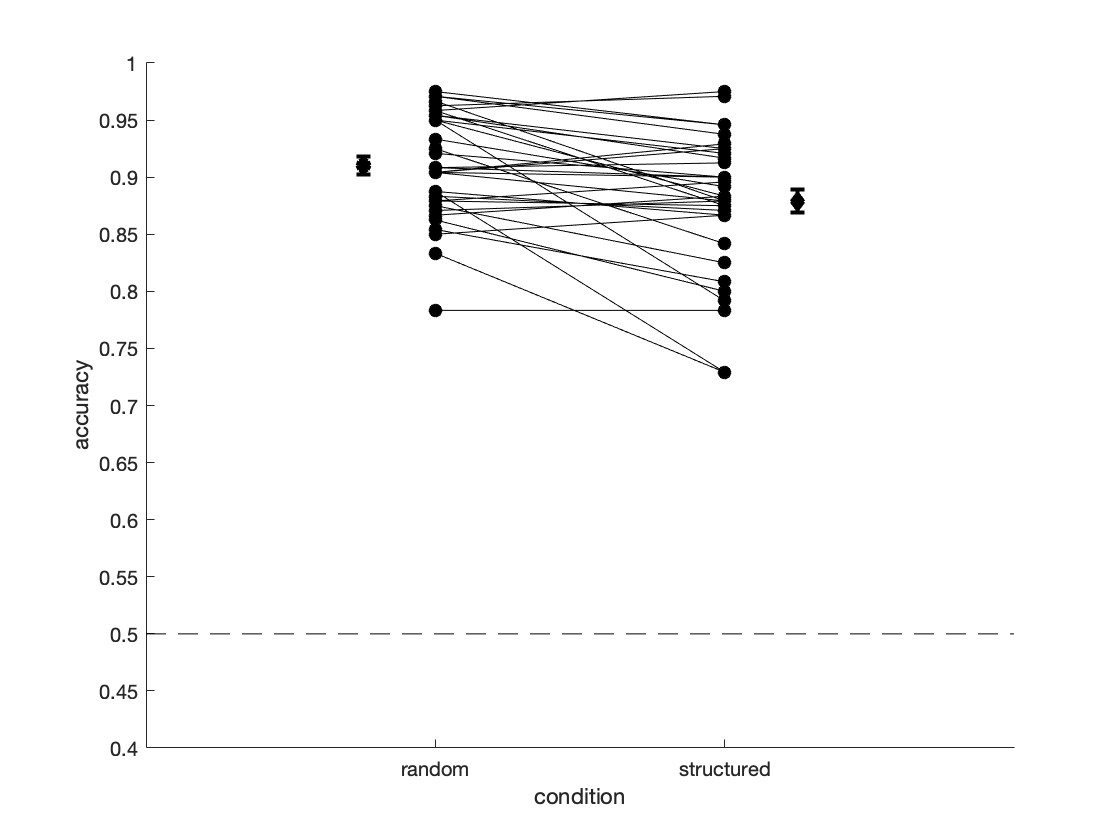

[rand_acc,struct_acc] = deal(nan(numel(subj_list),1)); %initialise with NaN values
[rand_acc_1,rand_acc_2,struct_acc_1,struct_acc_2] = deal(nan(numel(subj_list),1));  %initialise with NaN values

%extract the mean of accuracy for each participant in random and structured conditions
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %per condition
    rand_acc(i_s) = nanmean(data_struct(subj).RandomCorrect);
    struct_acc(i_s) = nanmean(data_struct(subj).StructCorrect);
    
    %per block
    rand_acc_1(i_s) = nanmean(data_struct(subj).RandomCorrect(1:120));
    rand_acc_2(i_s) = nanmean(data_struct(subj).RandomCorrect(121:240));
    struct_acc_1(i_s) = nanmean(data_struct(subj).StructCorrect(1:120));
    struct_acc_2(i_s) = nanmean(data_struct(subj).StructCorrect(121:240));
end

%useful values
rand_acc_mean = nanmean(rand_acc); %random condition mean
rand_acc_std = nanstd(rand_acc); %random condition std
rand_acc_sem = rand_acc_std/sqrt(length(rand_acc));
rand_acc_mean_1 = nanmean(rand_acc_1); %random block 1 mean
rand_acc_std_1 = nanstd(rand_acc_1); %random block 1 std
rand_acc_mean_2 = nanmean(rand_acc_2); %random block 2 mean
rand_acc_std_2 = nanstd(rand_acc_2); %random block 2 std
struct_acc_mean = nanmean(struct_acc); %structured condition mean
struct_acc_std = nanstd(struct_acc); %structured condition std
struct_acc_sem = struct_acc_std/sqrt(length(struct_acc));
struct_acc_mean_1 = nanmean(struct_acc_1); %structured block 1 mean
struct_acc_std_1 = nanstd(struct_acc_1); %structured block 1 std
struct_acc_mean_2 = nanmean(struct_acc_2); %structured block 2 mean
struct_acc_std_2 = nanstd(struct_acc_2); %structured block 2 std

%plot mean accuracy for each participant for both conditions
figure; hold on;
plot([rand_acc';struct_acc'], '-ok','MarkerFaceColor','k')
errorbar(0.75,rand_acc_mean,rand_acc_sem,'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,struct_acc_mean,struct_acc_sem,'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylim([0.4,1]); ylabel('accuracy');
set(gca,'ytick',[0.4:0.05:1])
xlim([0,3]); xlabel('condition');
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});
plot([0,3],[0.5,0.5],'k--')

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanAccuracy','-dpng','-r600');

sprintf('Random Accuracy (mean ± std) = %.2f ± %.2f; Structured Accuracy (mean, std) = %.2f ± %.2f',...
    rand_acc_mean, rand_acc_std, struct_acc_mean, struct_acc_std)

ans = 'Random Accuracy (mean ± std) = 0.91 ± 0.05; Structured Accuracy (mean, std) = 0.88 ± 0.06'

%check significance
[h,p,ci,stats] = ttest(rand_acc,0.5);
sprintf(['Significance test: Accuracy in random condition compared to 0.5:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Accuracy in random condition compared to 0.5: t(34)=53.04, p=0.00000'

[h,p,ci,stats] = ttest(struct_acc,0.5);
sprintf(['Significance test: Accuracy in structured condition compared to 0.5:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Accuracy in structured condition compared to 0.5: t(34)=37.58, p=0.00000'

[h,p,ci,stats] = ttest(rand_acc,struct_acc);
sprintf(['Significance test: Difference in accuracy between random and structured conditions:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in accuracy between random and structured conditions: t(34)=4.00, p=0.00032'

## Confidence

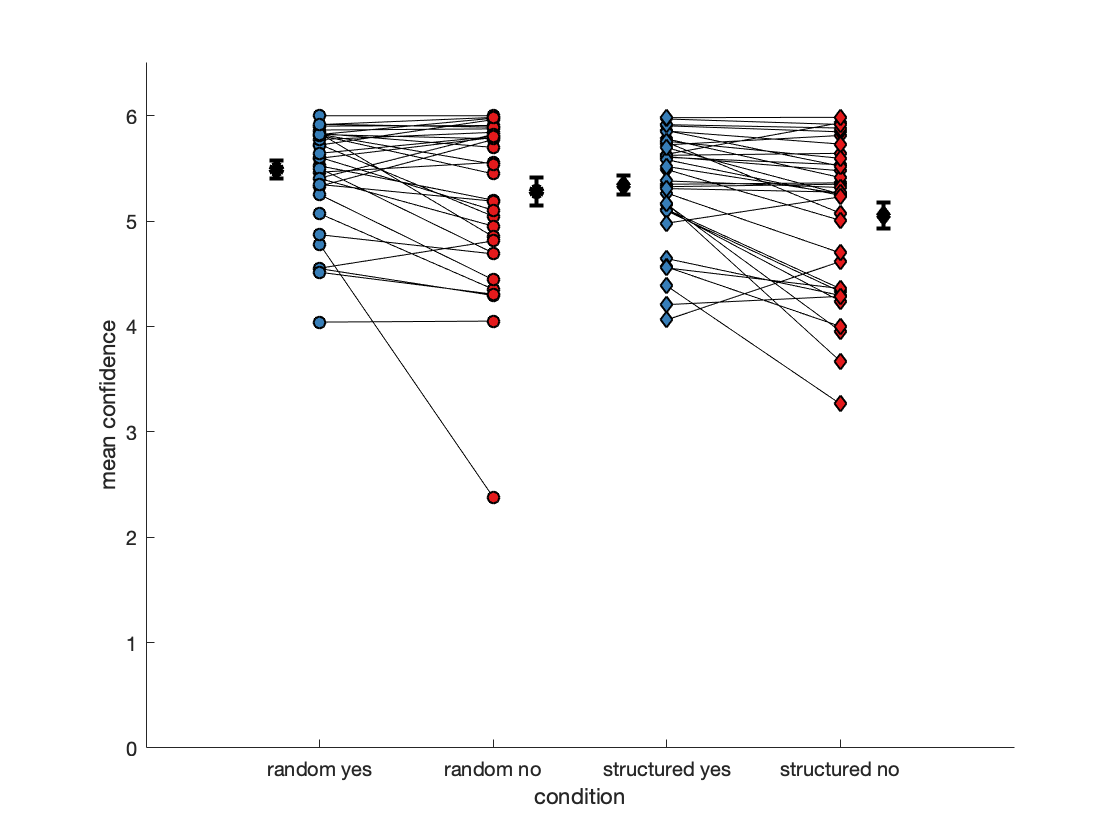

[rand_yes_conf,rand_no_conf,struct_yes_conf, struct_no_conf] = deal(nan(1,numel(subj_list))); %initialise with NaN values

%extract the mean of confidence for each participant in random and structured conditions
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_yes_conf(i_s) = nanmean(data_struct(subj).RandomConf(data_struct(subj).RandomResp==1));
    rand_no_conf(i_s) = nanmean(data_struct(subj).RandomConf(data_struct(subj).RandomResp==0));
    struct_yes_conf(i_s) = nanmean(data_struct(subj).StructConf(data_struct(subj).StructResp==1));
    struct_no_conf(i_s) = nanmean(data_struct(subj).StructConf(data_struct(subj).StructResp==0));
end

%useful values
[rand_yes_conf_mean,rand_no_conf_mean,struct_yes_conf_mean, struct_no_conf_mean] = ...
    deal(nanmean(rand_yes_conf),nanmean(rand_no_conf),nanmean(struct_yes_conf),nanmean(struct_no_conf));
[rand_yes_conf_std,rand_no_conf_std,struct_yes_conf_std, struct_no_conf_std] = ...
    deal(nanstd(rand_yes_conf),nanstd(rand_no_conf),nanstd(struct_yes_conf),nanstd(struct_no_conf));

%plot mean confidence for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_conf;rand_no_conf],'k');
plot(3:4,[struct_yes_conf;struct_no_conf],'k');
scatter(ones(length(subj_list),1),rand_yes_conf,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_conf,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_conf,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_conf,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
errorbar(0.75,rand_yes_conf_mean,rand_yes_conf_std/sqrt(length(rand_yes_conf)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_no_conf_mean,rand_no_conf_std/sqrt(length(rand_no_conf)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_yes_conf_mean,struct_yes_conf_std/sqrt(length(struct_yes_conf)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_no_conf_mean,struct_no_conf_std/sqrt(length(struct_no_conf)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylim([0,6.5]); ylabel('mean confidence');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanConfidence','-dpng','-r600');

sprintf('Random Yes Confidence (mean ± std) = %.2f ± %.2f; Random No Confidence (mean, std) = %.2f ± %.2f',...
    rand_yes_conf_mean, rand_yes_conf_std, rand_no_conf_mean, rand_no_conf_std)

ans = 'Random Yes Confidence (mean ± std) = 5.49 ± 0.50; Random No Confidence (mean, std) = 5.28 ± 0.79'

sprintf('Structured Yes Confidence (mean ± std) = %.2f ± %.2f; Structured No Confidence (mean, std) = %.2f ± %.2f',...
    struct_yes_conf_mean, struct_yes_conf_std, struct_no_conf_mean, struct_no_conf_std)

ans = 'Structured Yes Confidence (mean ± std) = 5.34 ± 0.52; Structured No Confidence (mean, std) = 5.05 ± 0.72'

%check significance
[h,p,ci,stats] = ttest(rand_yes_conf,struct_yes_conf);
sprintf(['Significance test: Difference in mean confidence in "yes" responses between random:' ...
    ' and sturctured conditions: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean confidence in "yes" responses between random: and sturctured conditions: t(34)=3.01, p=0.00493'

[h,p,ci,stats] = ttest(rand_no_conf,struct_no_conf);
sprintf(['Significance test: Difference in mean confidence in "no" responses between random:' ...
    ' and sturctured conditions: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean confidence in "no" responses between random: and sturctured conditions: t(34)=2.70, p=0.01061'

[h,p,ci,stats] = ttest(rand_yes_conf,rand_no_conf);
sprintf(['Significance test: Difference in mean confidence in the random condition between:' ...
    ' yes and no responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean confidence in the random condition between: yes and no responses: t(34)=2.37, p=0.02337'

[h,p,ci,stats] = ttest(struct_yes_conf,struct_no_conf);
sprintf(['Significance test: Difference in mean confidence in the structured condition between:' ...
    ' yes and no responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean confidence in the structured condition between: yes and no responses: t(34)=3.92, p=0.00041'

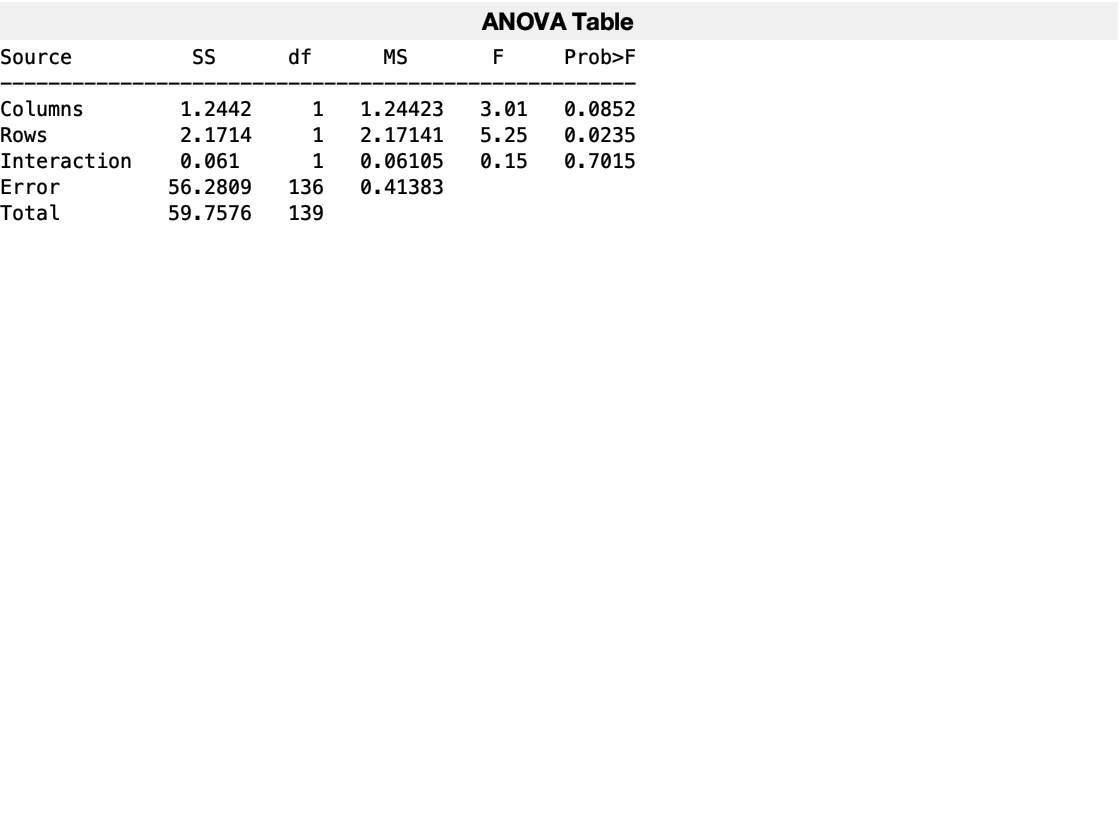

subj_mat_raw = [rand_yes_conf',rand_no_conf',struct_yes_conf',struct_no_conf'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_conf_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_conf_vec = [subj_mat(:,3);subj_mat(:,4)];
conf_mat = [rand_conf_vec,struct_conf_vec];
[p,tbl,stats] = anova2(conf_mat,length(conf_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between random and structured conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between random and structured conditions: F(1,136)=3.01, p=0.08519'

sprintf(['Significance test: Between yes and no responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between yes and no responses: F(1,136)=5.25, p=0.02352'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,136)=0.15, p=0.70152'

## Visibility-confidence correlation

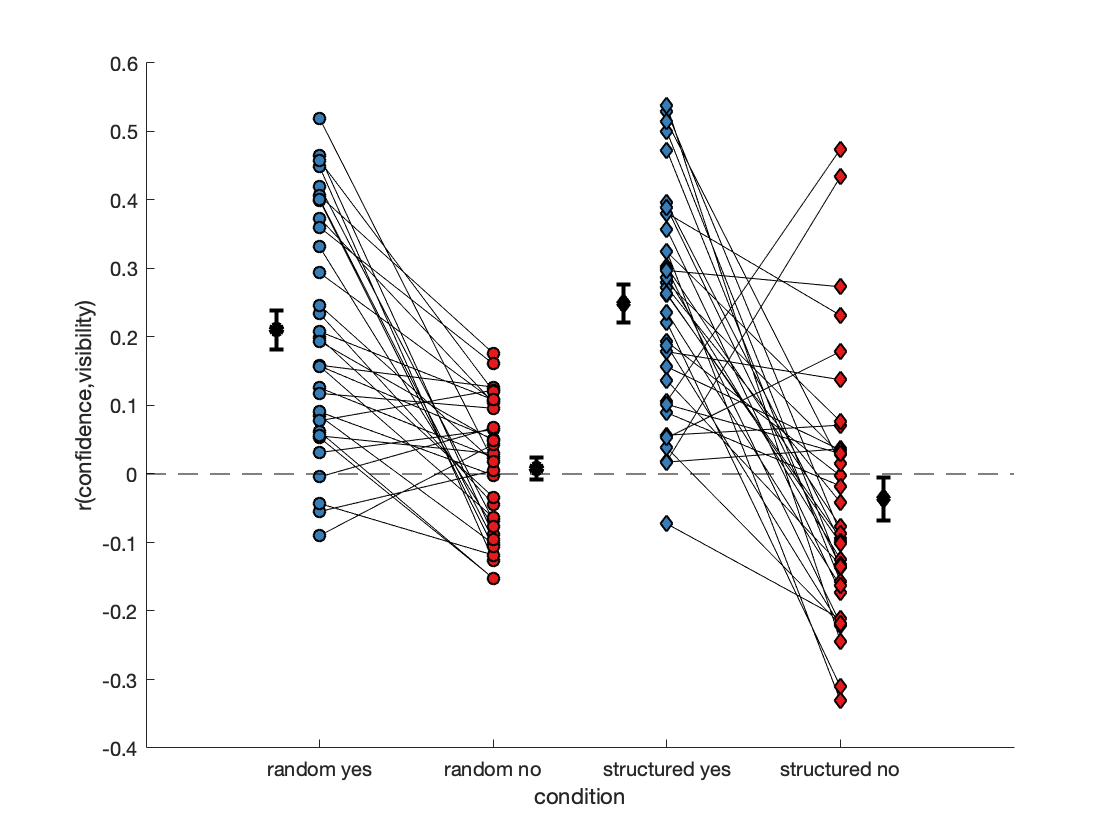

[rand_yes_VCcorr,struct_yes_VCcorr, rand_no_VCcorr, struct_no_VCcorr] = deal(nan(size(subj_list)));%initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned confidence and visibility vectors in both conditions
    demeaned_random_confidence = data_struct(subj).RandomDemeanConf;
    demeaned_struct_confidence = data_struct(subj).StructDemeanConf;
    demeaned_random_vis = data_struct(subj).RandomDemeanVisibility;
    demeaned_struct_vis = data_struct(subj).StructDemeanVisibility;
    
    %calculate the visibility-confidence correlation (Spearman's rank) for each participant
    
    %random condition
    rand_yes_VCcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    struct_yes_VCcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    %structured condition
    rand_no_VCcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1));
    struct_no_VCcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
end

%useful values
[rand_yes_VCcorr_mean,rand_no_VCcorr_mean,struct_yes_VCcorr_mean, struct_no_VCcorr_mean] = ...
    deal(nanmean(rand_yes_VCcorr),nanmean(rand_no_VCcorr),nanmean(struct_yes_VCcorr),nanmean(struct_no_VCcorr));
[rand_yes_VCcorr_std,rand_no_VCcorr_std,struct_yes_VCcorr_std, struct_no_VCcorr_std] = ...
    deal(nanstd(rand_yes_VCcorr),nanstd(rand_no_VCcorr),nanstd(struct_yes_VCcorr),nanstd(struct_no_VCcorr));

%plot the visibility-confidence correlation for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_VCcorr;rand_no_VCcorr],'k');
plot(3:4,[struct_yes_VCcorr;struct_no_VCcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_VCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_VCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_VCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_VCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
errorbar(0.75,rand_yes_VCcorr_mean,rand_yes_VCcorr_std/sqrt(length(rand_yes_VCcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_no_VCcorr_mean,rand_no_VCcorr_std/sqrt(length(rand_no_VCcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_yes_VCcorr_mean,struct_yes_VCcorr_std/sqrt(length(struct_yes_VCcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_no_VCcorr_mean,struct_no_VCcorr_std/sqrt(length(struct_no_VCcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylabel('r(confidence,visibility)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
plot([0,5],[0,0],'k--')

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrVisConf','-dpng','-r600');

sprintf(['Random Yes r(confidence,visibility) (mean ± std) = %.2f ± %.2f; ' ...
    'Random No r(confidence,visibility) (mean, std) = %.2f ± %.2f'],...
    rand_yes_VCcorr_mean, rand_yes_VCcorr_std, rand_no_VCcorr_mean, rand_no_VCcorr_std)

ans = 'Random Yes r(confidence,visibility) (mean ± std) = 0.21 ± 0.17; Random No r(confidence,visibility) (mean, std) = 0.01 ± 0.10'

sprintf(['Structured Yes r(confidence,visibility) (mean ± std) = %.2f ± %.2f; ' ...
    'Structured No r(confidence,visibility) (mean, std) = %.2f ± %.2f'],...
    struct_yes_VCcorr_mean, struct_yes_VCcorr_std, struct_no_VCcorr_mean, struct_no_VCcorr_std)

ans = 'Structured Yes r(confidence,visibility) (mean ± std) = 0.25 ± 0.16; Structured No r(confidence,visibility) (mean, std) = -0.04 ± 0.19'

%significance test
[h,p,ci,stats] = ttest(rand_yes_VCcorr);
sprintf(['Significance test: r(confidence,visibility) in random yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(confidence,visibility) in random yes: t(32)=7.01, p=0.00000'

[h,p,ci,stats] = ttest(rand_no_VCcorr);
sprintf(['Significance test: r(confidence,visibility) in random no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(confidence,visibility) in random no: t(32)=0.48, p=0.63201'

[h,p,ci,stats] = ttest(struct_yes_VCcorr);
sprintf(['Significance test: r(confidence,visibility) in structured yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(confidence,visibility) in structured yes: t(34)=9.20, p=0.00000'

[h,p,ci,stats] = ttest(struct_no_VCcorr);
sprintf(['Significance test: r(_VRT,visibility) in structured no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(_VRT,visibility) in structured no: t(34)=-1.14, p=0.26304'

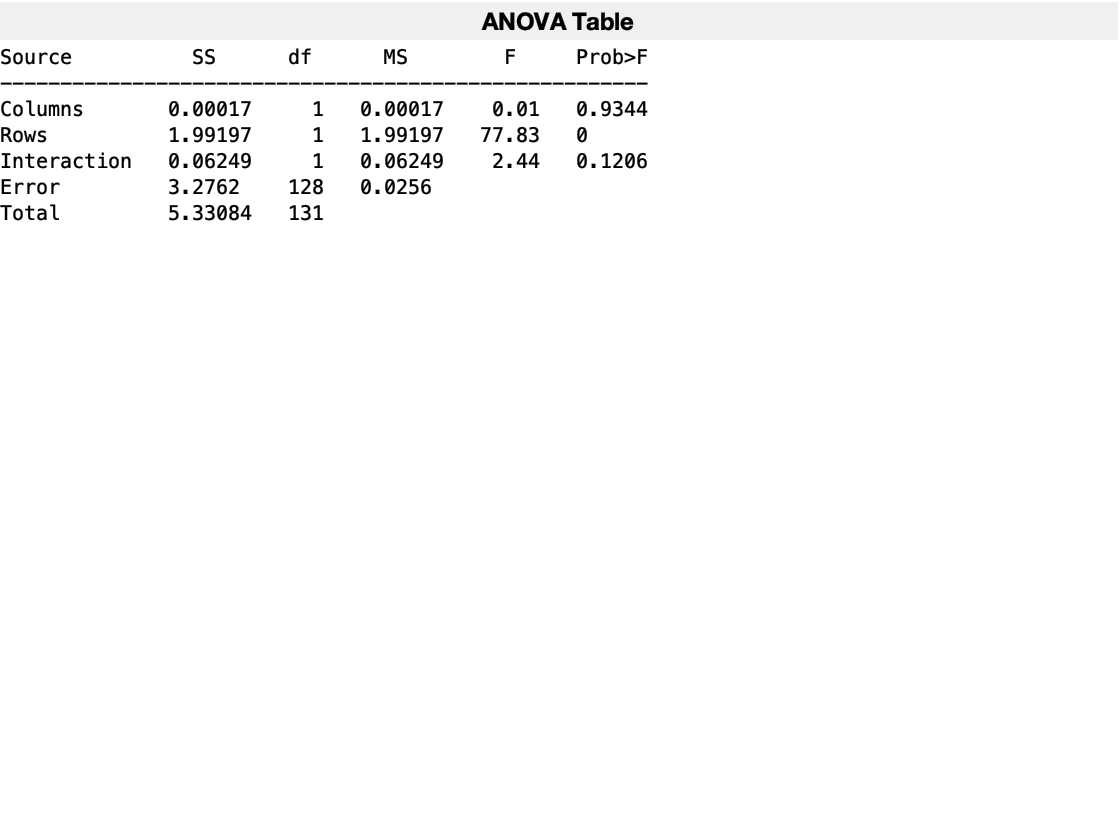

subj_mat_raw = [rand_yes_VCcorr',rand_no_VCcorr',struct_yes_VCcorr',struct_no_VCcorr'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_VCcorr_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_VCcorr_vec = [subj_mat(:,3);subj_mat(:,4)];
VCcorr_mat = [rand_VCcorr_vec,struct_VCcorr_vec];
[p,tbl,stats] = anova2(VCcorr_mat,length(VCcorr_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between structured and random conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between structured and random conditions: F(1,128)=0.01, p=0.93442'

sprintf(['Significance test: Between yes and no responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between yes and no responses: F(1,128)=77.83, p=0.00000'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,128)=2.44, p=0.12064'

## Response bias

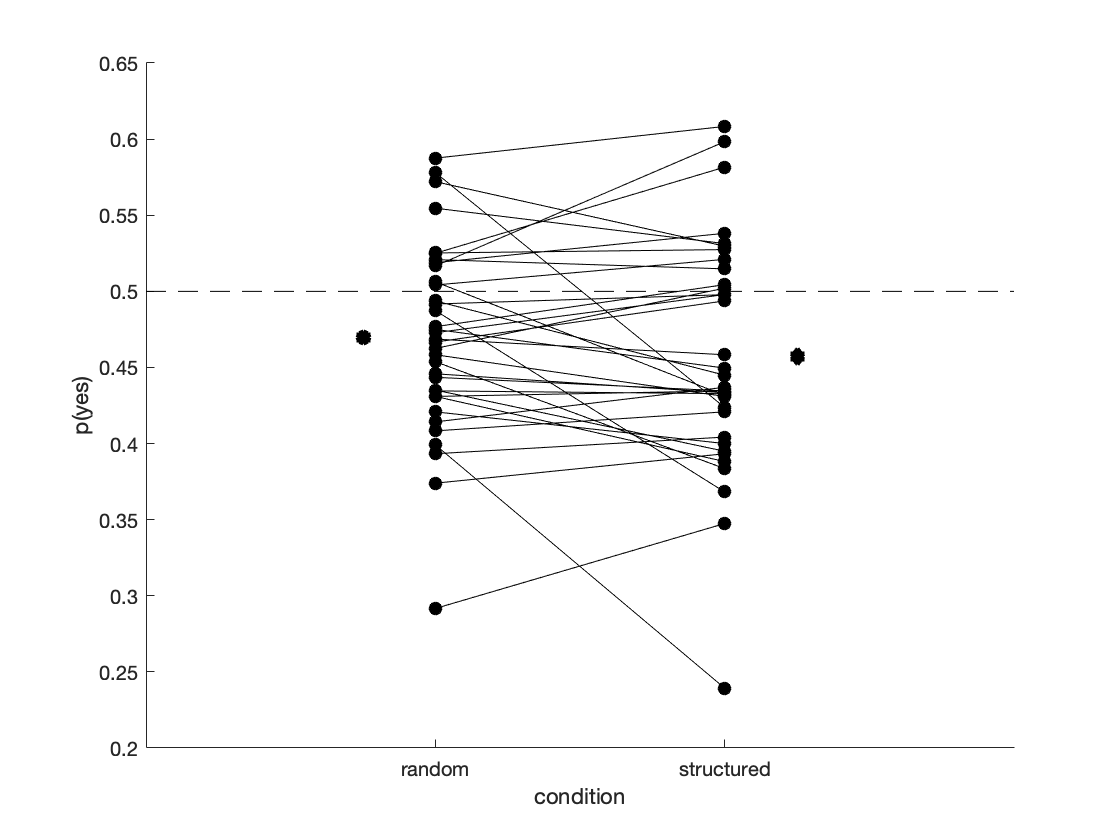

[rand_Pyes,struct_Pyes] = deal(nan(numel(subj_list),1)); %initialise with NaN values

%extract the probability of saying "yes" (p(yes)) for each participant in
% random and structured conditions, igoring NaN responses
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    rand_Pyes(i_s) = nanmean(data_struct(subj).RandomResp);
    struct_Pyes(i_s) = nanmean(data_struct(subj).StructResp);
end

%useful values
[rand_Pyes_mean,struct_Pyes_mean] = ...
    deal(nanmean(rand_Pyes),nanmean(struct_Pyes));
[rand_Pyes_std,struct_Pyes_std] = ...
    deal(nanstd(rand_Pyes),nanstd(struct_Pyes));

%plot p(yes) for each participant for both conditions
figure; hold on;
plot([rand_Pyes';struct_Pyes'],'-ok','MarkerFaceColor','k');
errorbar(0.75,rand_Pyes_mean,rand_Pyes_std/length(subj_list),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,struct_Pyes_mean,struct_Pyes_std/length(subj_list),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylabel('p(yes)');
xlim([0,3]); xlabel('condition');
set(gca,'ytick',[0.2:0.05:1])
set(gca,'xtick',[1:2],'xticklabel',{'random','structured'});
plot([0,3],[0.5,0.5],'k--')

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/responseBias','-dpng','-r600');

sprintf('Random p(Yes) (mean ± std) = %.2f ± %.2f; Structured p(Yes) (mean, std) = %.2f ± %.2f',...
    rand_Pyes_mean, rand_Pyes_std, struct_Pyes_mean, struct_Pyes_std)

ans = 'Random p(Yes) (mean ± std) = 0.47 ± 0.06; Structured p(Yes) (mean, std) = 0.46 ± 0.08'

%check significance
[h,p,ci,stats] = ttest(rand_Pyes,0.5);
sprintf(['Significance test: p(yes) (response bias) in the ' ...
    'random condition: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: p(yes) (response bias) in the random condition: t(34)=-2.92, p=0.006'

[h,p,ci,stats] = ttest(struct_Pyes,0.5);
sprintf(['Significance test: p(yes) (response bias) in the ' ...
    'structured condition: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: p(yes) (response bias) in the structured condition: t(34)=-3.35, p=0.002'

[h,p,ci,stats] = ttest(rand_Pyes,struct_Pyes);
sprintf(['Significance test: Difference in p(yes) (response bias) between the ' ...
    'structured and random conditions: t(%d)=%.2f, p=%.3f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in p(yes) (response bias) between the structured and random conditions: t(34)=1.39, p=0.174'

## Visibility-response correlation

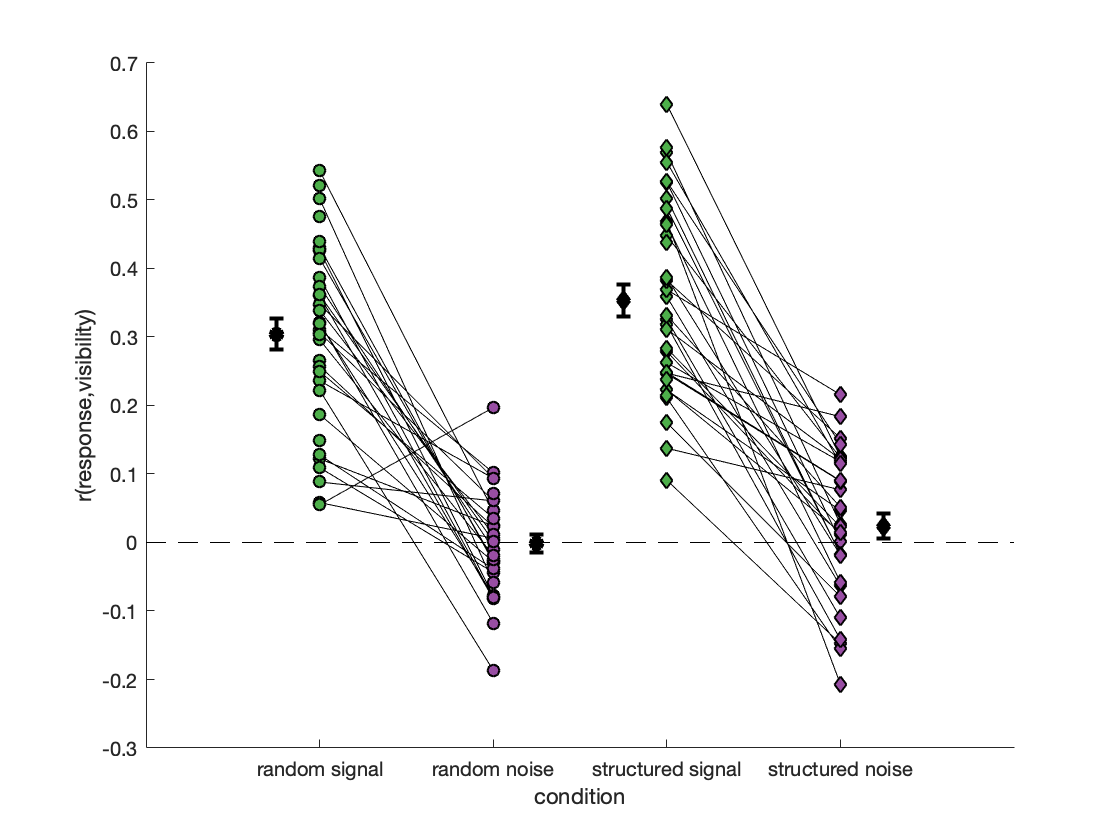

[rand_signal_Vresp_corr,rand_noise_Vresp_corr,struct_signal_Vresp_corr,struct_noise_Vresp_corr]...
    = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    subject = data_struct(subj);
    
    %calculate the visibility-response correlation (Spearman's rank) for each participant in "yes" and "no" responses
    
    %random condition
    rand_signal_Vresp_corr(i_s) = nancorr(subject.RandomDemeanVisibility(subject.RandomSignal==1),...
        subject.RandomResp(subject.RandomSignal==1));
    rand_noise_Vresp_corr(i_s) = nancorr(subject.RandomDemeanVisibility(subject.RandomSignal==0),...
        subject.RandomResp(subject.RandomSignal==0));
    %structured condition
    struct_signal_Vresp_corr(i_s) = nancorr(subject.StructDemeanVisibility(subject.StructSignal==1),...
        subject.StructResp(subject.StructSignal==1));
    struct_noise_Vresp_corr(i_s) = nancorr(subject.StructDemeanVisibility(subject.StructSignal==0),...
        subject.StructResp(subject.StructSignal==0));
end

%useful values
[rand_signal_Vresp_corr_mean,rand_noise_Vresp_corr_mean,struct_signal_Vresp_corr_mean, struct_noise_Vresp_corr_mean] = ...
    deal(nanmean(rand_signal_Vresp_corr),nanmean(rand_noise_Vresp_corr),nanmean(struct_signal_Vresp_corr),nanmean(struct_noise_Vresp_corr));
[rand_signal_Vresp_corr_std,rand_noise_Vresp_corr_std,struct_signal_Vresp_corr_std, struct_noise_Vresp_corr_std] = ...
    deal(nanstd(rand_signal_Vresp_corr),nanstd(rand_noise_Vresp_corr),nanstd(struct_signal_Vresp_corr),nanstd(struct_noise_Vresp_corr));

%plot the visibility-response correlation for each participant for both conditions and responses
figure; hold on;
plot(1:2,[rand_signal_Vresp_corr;rand_noise_Vresp_corr],'k');
plot(3:4,[struct_signal_Vresp_corr;struct_noise_Vresp_corr],'k');
scatter(ones(length(subj_list),1),rand_signal_Vresp_corr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_noise_Vresp_corr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_signal_Vresp_corr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_noise_Vresp_corr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
errorbar(0.75,rand_signal_Vresp_corr_mean,rand_signal_Vresp_corr_std/sqrt(length(rand_signal_Vresp_corr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_noise_Vresp_corr_mean,rand_noise_Vresp_corr_std/sqrt(length(rand_noise_Vresp_corr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_signal_Vresp_corr_mean,struct_signal_Vresp_corr_std/sqrt(length(struct_signal_Vresp_corr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_noise_Vresp_corr_mean,struct_noise_Vresp_corr_std/sqrt(length(struct_noise_Vresp_corr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylabel('r(response,visibility)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random signal','random noise','structured signal','structured noise'})
plot([0,5],[0,0],'k--')
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrVisResp','-dpng','-r600');

%check significance
[h,p,ci,stats] = ttest(rand_signal_Vresp_corr);
sprintf(['Significance test: r(response,visibility) in random signal:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),visibility) in random signal: t(33)=13.16, p=0.00000'

[h,p,ci,stats] = ttest(rand_noise_Vresp_corr);
sprintf(['Significance test: r(response,visibility) in random noise:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),visibility) in random noise: t(27)=-0.10, p=0.91922'

[h,p,ci,stats] = ttest(struct_signal_Vresp_corr);
sprintf(['Significance test: r(response,visibility) in structured signal:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),visibility) in structured signal: t(34)=14.98, p=0.00000'

[h,p,ci,stats] = ttest(struct_noise_Vresp_corr);
sprintf(['Significance test: r(response,visibility) in structured noise:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),visibility) in structured noise: t(29)=1.20, p=0.23958'

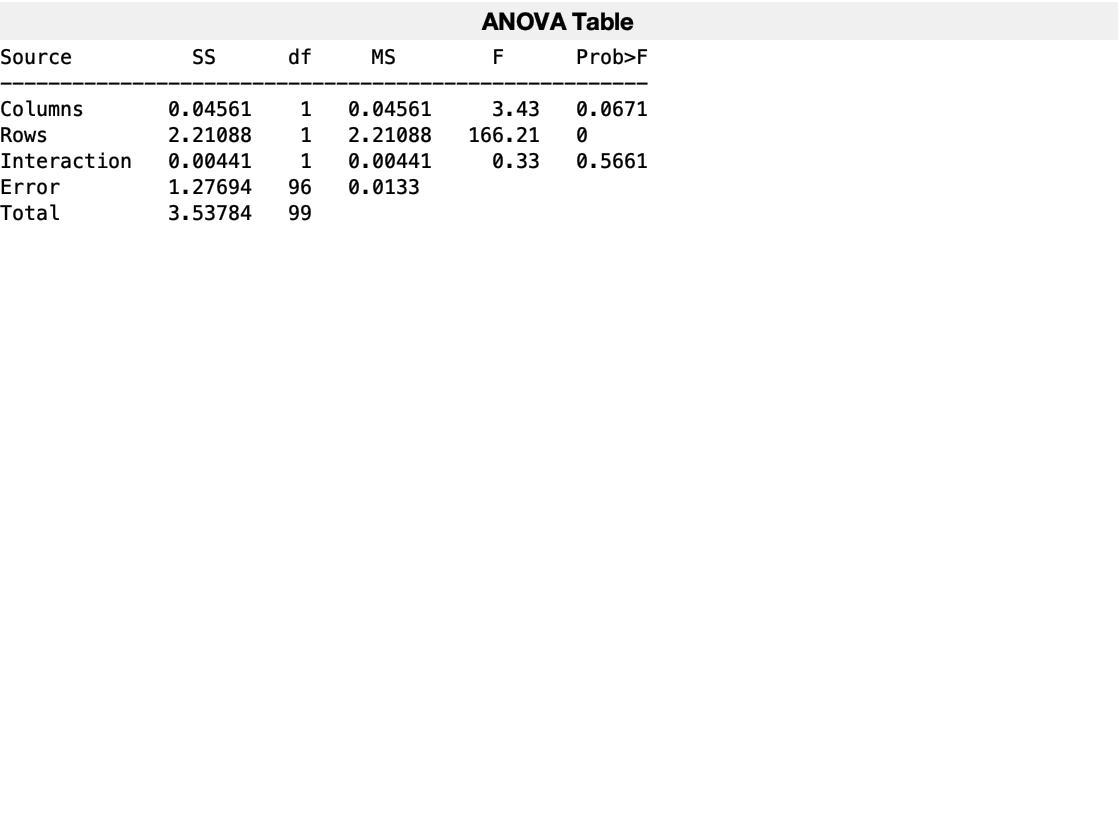

subj_mat_raw = [rand_signal_Vresp_corr',rand_noise_Vresp_corr',struct_signal_Vresp_corr',struct_noise_Vresp_corr'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_Vresp_corr_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_Vresp_corr_vec = [subj_mat(:,3);subj_mat(:,4)];
Vresp_corr_mat = [rand_Vresp_corr_vec,struct_Vresp_corr_vec];
[p,tbl,stats] = anova2(Vresp_corr_mat,length(Vresp_corr_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between structured and random conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between structured and random conditions: F(1,96)=3.43, p=0.06712'

sprintf(['Significance test: Between signal and noise responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between signal and noise responses: F(1,96)=166.21, p=0.00000'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,96)=0.33, p=0.56609'

## Response Time

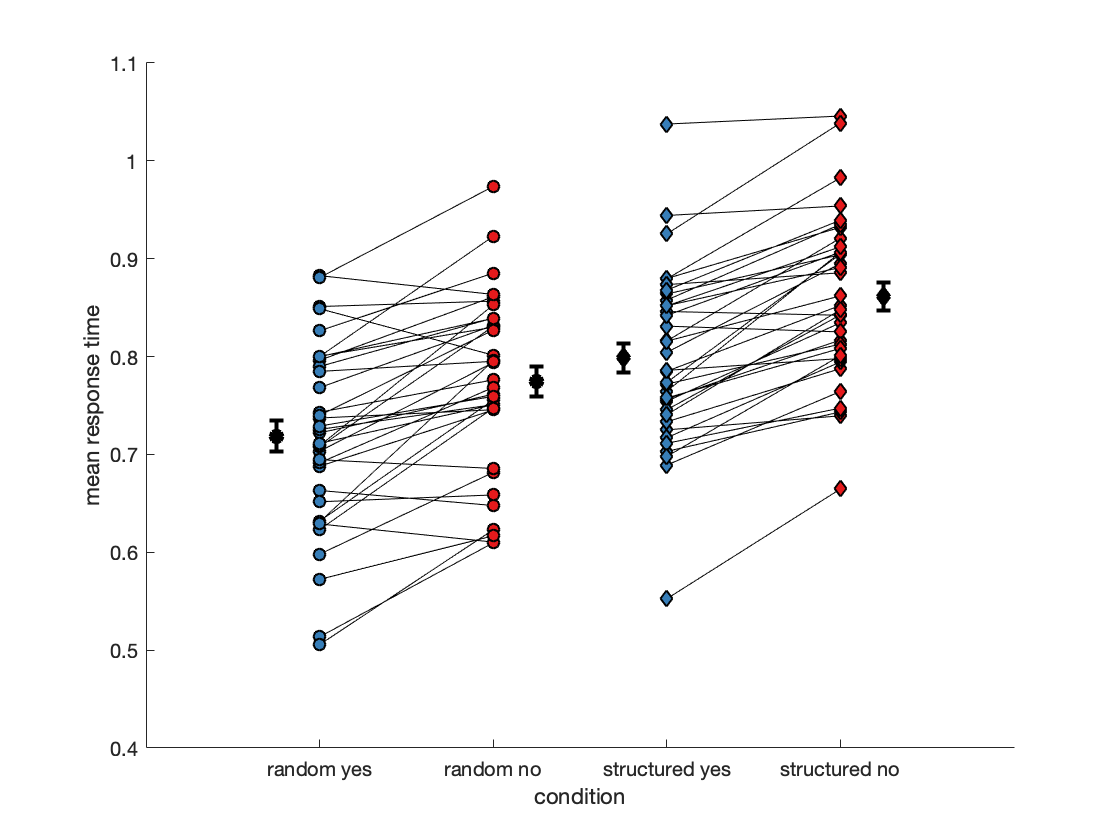

[rand_yes_RT,rand_no_RT,struct_yes_RT, struct_no_RT] = deal(nan(1,numel(subj_list))); %initialise with NaN values

%extract the mean of response time (log(RT)) for each participant in random and structured conditions
for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    rand_yes_RT(i_s) = nanmean(data_struct(subj).RandomRT(data_struct(subj).RandomResp==1));
    rand_no_RT(i_s) = nanmean(data_struct(subj).RandomRT(data_struct(subj).RandomResp==0));
    struct_yes_RT(i_s) = nanmean(data_struct(subj).StructRT(data_struct(subj).StructResp==1));
    struct_no_RT(i_s) = nanmean(data_struct(subj).StructRT(data_struct(subj).StructResp==0));
end

%useful values
[rand_yes_RT_mean,rand_no_RT_mean,struct_yes_RT_mean, struct_no_RT_mean] = ...
    deal(nanmean(rand_yes_RT),nanmean(rand_no_RT),nanmean(struct_yes_RT),nanmean(struct_no_RT));
[rand_yes_RT_std,rand_no_RT_std,struct_yes_RT_std, struct_no_RT_std] = ...
    deal(nanstd(rand_yes_RT),nanstd(rand_no_RT),nanstd(struct_yes_RT),nanstd(struct_no_RT));

%plot the mean log(RT) for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_RT;rand_no_RT],'k');
plot(3:4,[struct_yes_RT;struct_no_RT],'k');
scatter(ones(length(subj_list),1),rand_yes_RT,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_RT,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_RT,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_RT,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
errorbar(0.75,rand_yes_RT_mean,rand_yes_RT_std/sqrt(length(rand_yes_RT)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_no_RT_mean,rand_no_RT_std/sqrt(length(rand_no_RT)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_yes_RT_mean,struct_yes_RT_std/sqrt(length(struct_yes_RT)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_no_RT_mean,struct_no_RT_std/sqrt(length(struct_no_RT)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylim([0.4,1.1]); ylabel('mean log(response time)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/meanRT','-dpng','-r600');

sprintf('Random Yes RT (mean ± std) = %.2f ± %.2f; Random No RT (mean, std) = %.2f ± %.2f',...
    rand_yes_RT_mean, rand_yes_RT_std, rand_no_RT_mean, rand_no_RT_std)

ans = 'Random Yes RT (mean ± std) = 0.72 ± 0.09; Random No RT (mean, std) = 0.77 ± 0.09'

sprintf('Structured Yes RT (mean ± std) = %.2f ± %.2f; Structured No RT (mean, std) = %.2f ± %.2f',...
    struct_yes_RT_mean, struct_yes_RT_std, struct_no_RT_mean, struct_no_RT_std)

ans = 'Structured Yes RT (mean ± std) = 0.80 ± 0.09; Structured No RT (mean, std) = 0.86 ± 0.08'

%check significance
[h,p,ci,stats] = ttest(rand_yes_RT,struct_yes_RT);
sprintf(['Significance test: Difference in mean RT in "yes" responses between random:' ...
    ' and sturctured conditions: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean RT in "yes" responses between random: and sturctured conditions: t(34)=-10.03, p=0.00000'

[h,p,ci,stats] = ttest(rand_no_RT,struct_no_RT);
sprintf(['Significance test: Difference in mean RT in "no" responses between random:' ...
    ' and sturctured conditions: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean RT in "no" responses between random: and sturctured conditions: t(34)=-10.55, p=0.00000'

[h,p,ci,stats] = ttest(rand_yes_RT,rand_no_RT);
sprintf(['Significance test: Difference in mean RT in the random condition between:' ...
    ' yes and no responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean RT in the random condition between: yes and no responses: t(34)=-6.31, p=0.00000'

[h,p,ci,stats] = ttest(struct_yes_RT,struct_no_RT);
sprintf(['Significance test: Difference in mean RT in the structured condition between:' ...
    ' yes and no responses: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in mean RT in the structured condition between: yes and no responses: t(34)=-9.47, p=0.00000'

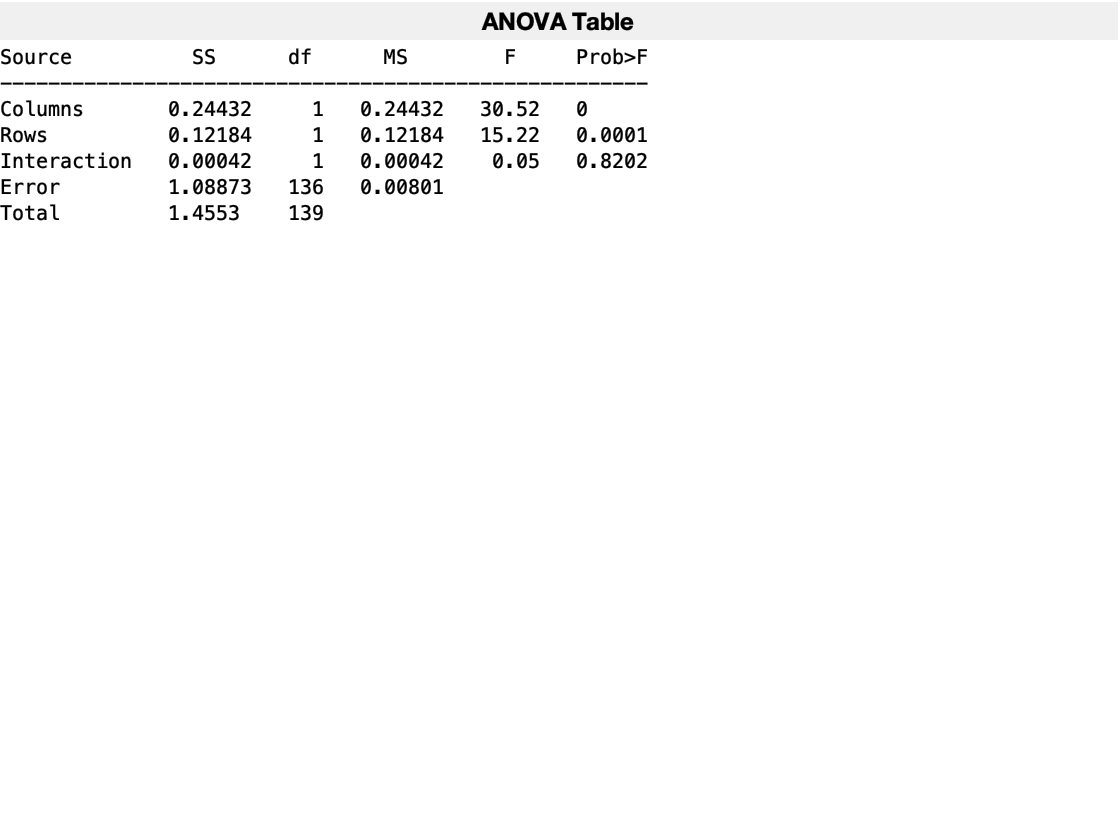

subj_mat_raw = [rand_yes_RT',rand_no_RT',struct_yes_RT',struct_no_RT'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_RT_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_RT_vec = [subj_mat(:,3);subj_mat(:,4)];
RT_mat = [rand_RT_vec,struct_RT_vec];
[p,tbl,stats] = anova2(RT_mat,length(RT_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between structured and random conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between structured and random conditions: F(1,136)=30.52, p=0.00000'

sprintf(['Significance test: Between yes and no responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between yes and no responses: F(1,136)=15.22, p=0.00015'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,136)=0.05, p=0.82017'

## Visibility-RT correlation

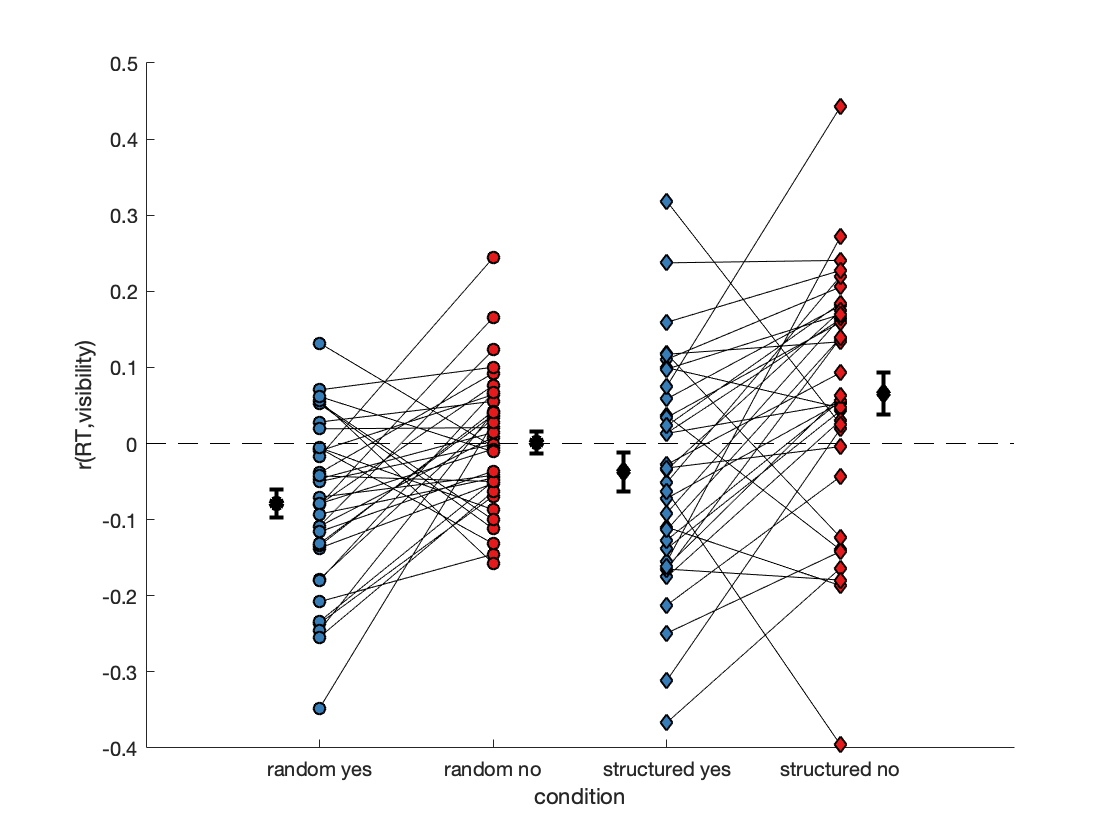

[rand_yes_VRTcorr,struct_yes_VRTcorr, rand_no_VRTcorr, struct_no_VRTcorr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned log(RT) and visibility vectors in both conditions
    demeaned_random_RT = data_struct(subj).RandomDemeanRT;
    demeaned_struct_RT = data_struct(subj).StructDemeanRT;
    demeaned_random_vis = data_struct(subj).RandomDemeanVisibility;
    demeaned_struct_vis = data_struct(subj).StructDemeanVisibility;
    
    %calculate the visibility-log(RT) correlation (Spearman's rank) for each participant
    
    %random condition
    rand_yes_VRTcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_RT(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    struct_yes_VRTcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_RT(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    %structured condition
    rand_no_VRTcorr(i_s) = nancorr(demeaned_random_vis(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1),...
        demeaned_random_RT(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1));
    struct_no_VRTcorr(i_s) = nancorr(demeaned_struct_vis(data_struct(subj).StructResp==0  & data_struct(subj).StructCorrect==1),...
        demeaned_struct_RT(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
end

%useful values
[rand_yes_VRTcorr_mean,rand_no_VRTcorr_mean,struct_yes_VRTcorr_mean, struct_no_VRTcorr_mean] = ...
    deal(nanmean(rand_yes_VRTcorr),nanmean(rand_no_VRTcorr),nanmean(struct_yes_VRTcorr),nanmean(struct_no_VRTcorr));
[rand_yes_VRTcorr_std,rand_no_VRTcorr_std,struct_yes_VRTcorr_std, struct_no_VRTcorr_std] = ...
    deal(nanstd(rand_yes_VRTcorr),nanstd(rand_no_VRTcorr),nanstd(struct_yes_VRTcorr),nanstd(struct_no_VRTcorr));

%plot the visibility-log(RT) correlation for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_VRTcorr;rand_no_VRTcorr],'k');
plot(3:4,[struct_yes_VRTcorr;struct_no_VRTcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_VRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_VRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_VRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_VRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
errorbar(0.75,rand_yes_VRTcorr_mean,rand_yes_VRTcorr_std/sqrt(length(rand_yes_VRTcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_no_VRTcorr_mean,rand_no_VRTcorr_std/sqrt(length(rand_no_VRTcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_yes_VRTcorr_mean,struct_yes_VRTcorr_std/sqrt(length(struct_yes_VRTcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_no_VRTcorr_mean,struct_no_VRTcorr_std/sqrt(length(struct_no_VRTcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylabel('r(log(RT),visibility)');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
plot([0,5],[0,0],'k--')

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrVisRT','-dpng','-r600');

sprintf(['Random Yes r(RT,visibility) (mean ± std) = %.2f ± %.2f; ' ...
    'Random No r(RT,visibility) (mean, std) = %.2f ± %.2f'],...
    rand_yes_VRTcorr_mean, rand_yes_VRTcorr_std, rand_no_VRTcorr_mean, rand_no_VRTcorr_std)

ans = 'Random Yes r(RT,visibility) (mean ± std) = -0.08 ± 0.11; Random No r(RT,visibility) (mean, std) = 0.00 ± 0.09'

sprintf(['Structured Yes r(RT,visibility) (mean ± std) = %.2f ± %.2f; ' ...
    'Structured No r(RT,visibility) (mean, std) = %.2f ± %.2f'],...
    struct_yes_VRTcorr_mean, struct_yes_VRTcorr_std, struct_no_VRTcorr_mean, struct_no_VRTcorr_std)

ans = 'Structured Yes r(RT,visibility) (mean ± std) = -0.04 ± 0.15; Structured No r(RT,visibility) (mean, std) = 0.07 ± 0.16'

%significance test
[h,p,ci,stats] = ttest(rand_yes_VRTcorr);
sprintf(['Significance test: r(RT,visibility) in random yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,visibility) in random yes: t(34)=-4.24, p=0.00016'

[h,p,ci,stats] = ttest(rand_no_VRTcorr);
sprintf(['Significance test: r(RT,visibility) in random no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,visibility) in random no: t(34)=0.10, p=0.92280'

[h,p,ci,stats] = ttest(struct_yes_VRTcorr);
sprintf(['Significance test: r(RT,visibility) in structured yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,visibility) in structured yes: t(34)=-1.47, p=0.14956'

[h,p,ci,stats] = ttest(struct_no_VRTcorr);
sprintf(['Significance test: r(RT,visibility) in structured no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,visibility) in structured no: t(34)=2.40, p=0.02223'

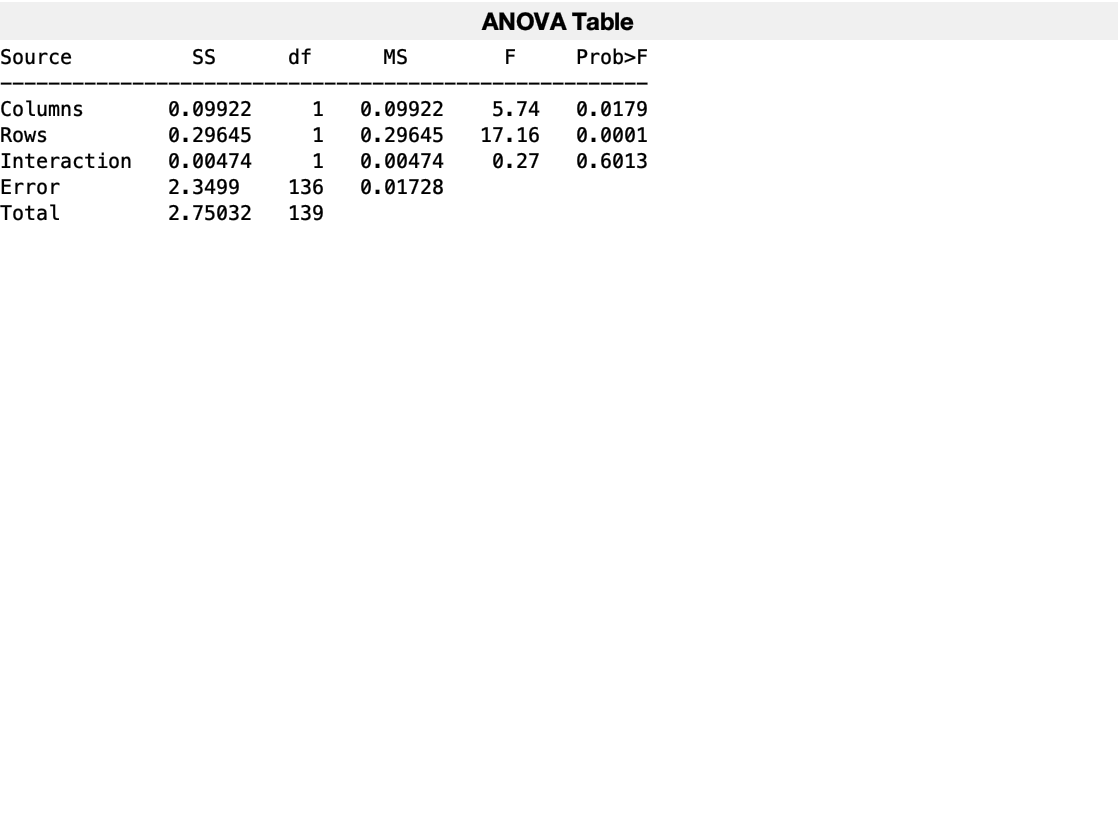

subj_mat_raw = [rand_yes_VRTcorr',rand_no_VRTcorr',struct_yes_VRTcorr',struct_no_VRTcorr'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_VRTcorr_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_VRTcorr_vec = [subj_mat(:,3);subj_mat(:,4)];
VRTcorr_mat = [rand_VRTcorr_vec,struct_VRTcorr_vec];
[p,tbl,stats] = anova2(VRTcorr_mat,length(VRTcorr_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between structured and random conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between structured and random conditions: F(1,136)=5.74, p=0.01792'

sprintf(['Significance test: Between yes and no responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between yes and no responses: F(1,136)=17.16, p=0.00006'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,136)=0.27, p=0.60127'

## E(Visibility)-confidence correlation

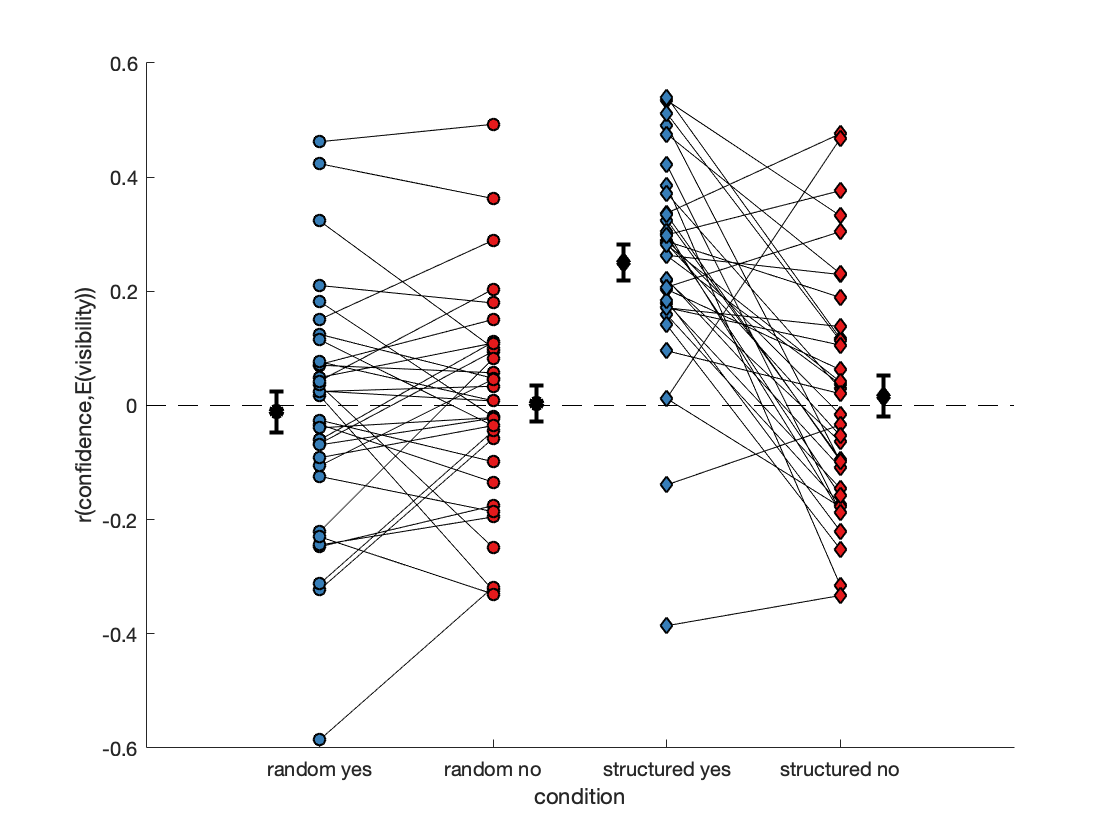

[rand_yes_EVCcorr,struct_yes_EVCcorr, rand_no_EVCcorr, struct_no_EVCcorr,...
    rand_yes_EVresCcorr, struct_yes_EVresCcorr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned expected visibility vectors for both conditions
    
    demeaned_random_Evis = data_struct(subj).RandomDemeanEV;
    demeaned_struct_Evis = data_struct(subj).StructDemeanEV;
    
    %extract residual expected visibility vectors (after correlating with visibility) for both conditions
    
    demeaned_random_Evis_res = data_struct(subj).RandomDemeanEVres;
    demeaned_struct_Evis_res = data_struct(subj).StructDemeanEVres;
    
    %extract demeaned confidence vectors for both conditions
    
    demeaned_random_confidence = data_struct(subj).RandomDemeanConf;
    demeaned_struct_confidence = data_struct(subj).StructDemeanConf;
    
    %calculate correlation between expected visibility and confidence
    
    %structured condition
    struct_yes_EVCcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    struct_no_EVCcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
    %random condition
    rand_yes_EVCcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    rand_no_EVCcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==0 & data_struct(subj).RandomCorrect==1));
    
    %calculate correlation between expected visibility residuals and confidence in "yes" responses
    
    %structured condition
    struct_yes_EVresCcorr(i_s) = nancorr(demeaned_struct_Evis_res(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_confidence(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    %random condition
    rand_yes_EVresCcorr(i_s) = nancorr(demeaned_random_Evis_res(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_confidence(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
end

%useful values
[rand_yes_EVCcorr_mean,rand_no_EVCcorr_mean,struct_yes_VCcorr_mean, struct_no_EVCcorr_mean] = ...
    deal(nanmean(rand_yes_EVCcorr),nanmean(rand_no_EVCcorr),nanmean(struct_yes_EVCcorr),nanmean(struct_no_EVCcorr));
[rand_yes_EVCcorr_std,rand_no_EVCcorr_std,struct_yes_VCcorr_std, struct_no_EVCcorr_std] = ...
    deal(nanstd(rand_yes_EVCcorr),nanstd(rand_no_EVCcorr),nanstd(struct_yes_EVCcorr),nanstd(struct_no_EVCcorr));

%plot correlation between expected visibility and confidence
figure; hold on;
plot(1:2,[rand_yes_EVCcorr;rand_no_EVCcorr],'k');
plot(3:4,[struct_yes_EVCcorr;struct_no_EVCcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_EVCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_EVCcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_EVCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_EVCcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
errorbar(0.75,rand_yes_EVCcorr_mean,rand_yes_EVCcorr_std/sqrt(length(rand_yes_EVCcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_no_EVCcorr_mean,rand_no_EVCcorr_std/sqrt(length(rand_no_EVCcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_yes_VCcorr_mean,struct_yes_VCcorr_std/sqrt(length(struct_yes_EVCcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_no_EVCcorr_mean,struct_no_EVCcorr_std/sqrt(length(struct_no_EVCcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylabel('r(confidence,E(visibility))');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
plot([0,5],[0,0],'k--')

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisConf','-dpng','-r600');

sprintf(['Random Yes r(confidence,E(visibility)) (mean ± std) = %.2f ± %.2f; ' ...
    'Random No r(confidence,E(visibility)) (mean, std) = %.2f ± %.2f'],...
    rand_yes_EVCcorr_mean, rand_yes_EVCcorr_std, rand_no_EVCcorr_mean, rand_no_EVCcorr_std)

ans = 'Random Yes r(confidence,E(visibility)) (mean ± std) = -0.01 ± 0.21; Random No r(confidence,E(visibility)) (mean, std) = 0.00 ± 0.19'

sprintf(['Structured Yes r(confidence,E(visibility)) (mean ± std) = %.2f ± %.2f; ' ...
    'Structured No r(confidence,E(visibility)) (mean, std) = %.2f ± %.2f'],...
    struct_yes_VCcorr_mean, struct_yes_VCcorr_std, struct_no_EVCcorr_mean, struct_no_EVCcorr_std)

ans = 'Structured Yes r(confidence,E(visibility)) (mean ± std) = 0.25 ± 0.19; Structured No r(confidence,E(visibility)) (mean, std) = 0.02 ± 0.21'

%significance test
[h,p,ci,stats] = ttest(rand_yes_EVCcorr);
sprintf(['Significance test: r(confidence,E(visibility)) in random yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(confidence,E(visibility)) in random yes: t(32)=-0.30, p=0.76325'

[h,p,ci,stats] = ttest(rand_no_EVCcorr);
sprintf(['Significance test: r(confidence,E(visibility)) in random no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(confidence,E(visibility)) in random no: t(32)=0.12, p=0.90412'

[h,p,ci,stats] = ttest(struct_yes_EVCcorr);
sprintf(['Significance test: r(confidence,E(visibility)) in structured yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(confidence,E(visibility)) in structured yes: t(34)=7.94, p=0.00000'

[h,p,ci,stats] = ttest(struct_no_EVCcorr);
sprintf(['Significance test: r(confidence,E(visibility)) in structured no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(confidence,E(visibility)) in structured no: t(34)=0.44, p=0.66010'

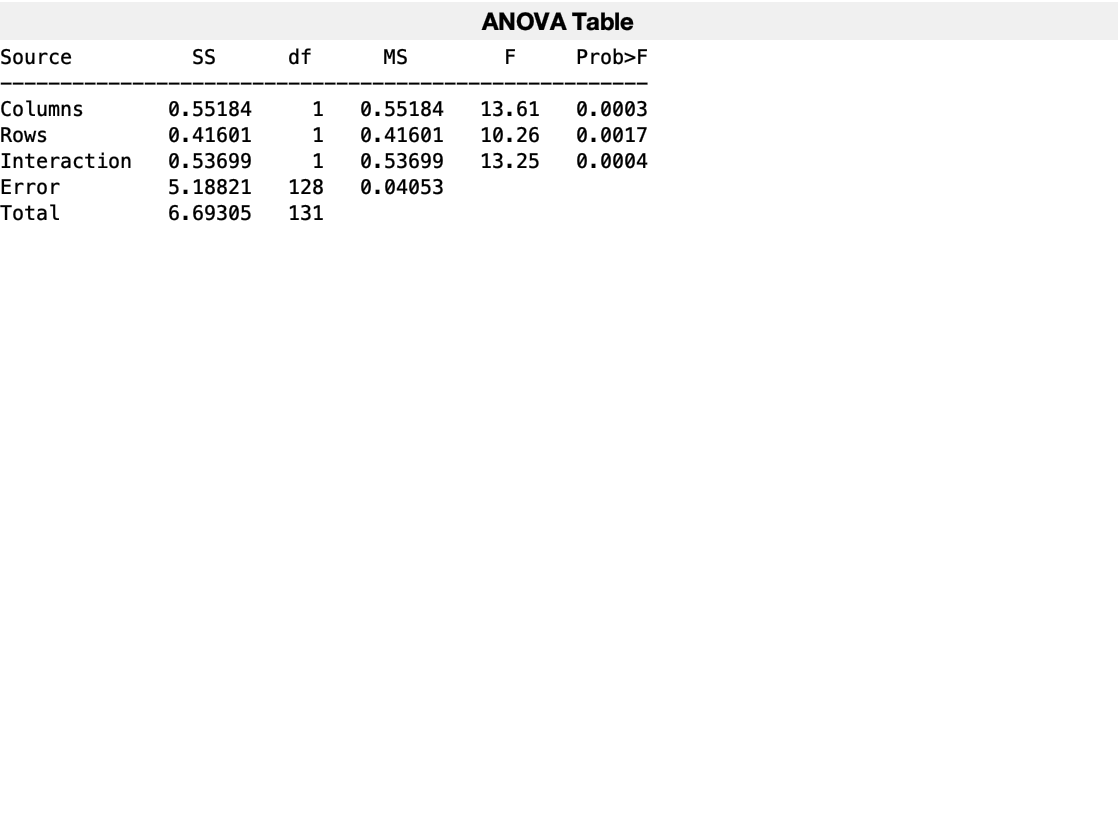

subj_mat_raw = [rand_yes_EVCcorr',rand_no_EVCcorr',struct_yes_EVCcorr',struct_no_EVCcorr'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_EVCcorr_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_EVCcorr_vec = [subj_mat(:,3);subj_mat(:,4)];
EVCcorr_mat = [rand_EVCcorr_vec,struct_EVCcorr_vec];
[p,tbl,stats] = anova2(EVCcorr_mat,length(EVCcorr_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between structured and random conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between structured and random conditions: F(1,128)=13.61, p=0.00033'

sprintf(['Significance test: Between yes and no responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between yes and no responses: F(1,128)=10.26, p=0.00171'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,128)=13.25, p=0.00039'

%further analysis
[h,p,ci,stats] = ttest(struct_yes_EVCcorr);
sprintf(['Significance test: E(visibility)-confidence correlations in "yes"' ...
    ' responses within the structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)-confidence correlations in "yes" responses within the structured condition: t(34)=7.94, p=0.00000'

[h,p,ci,stats] = ttest(struct_yes_EVresCcorr);
sprintf(['Significance test: E(visibility)_res-confidence correlations in "yes"' ...
    ' responses within the structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: E(visibility)_res-confidence correlations in "yes" responses within the structured condition: t(34)=2.36, p=0.02391'

## E(Visibility)-response correlation

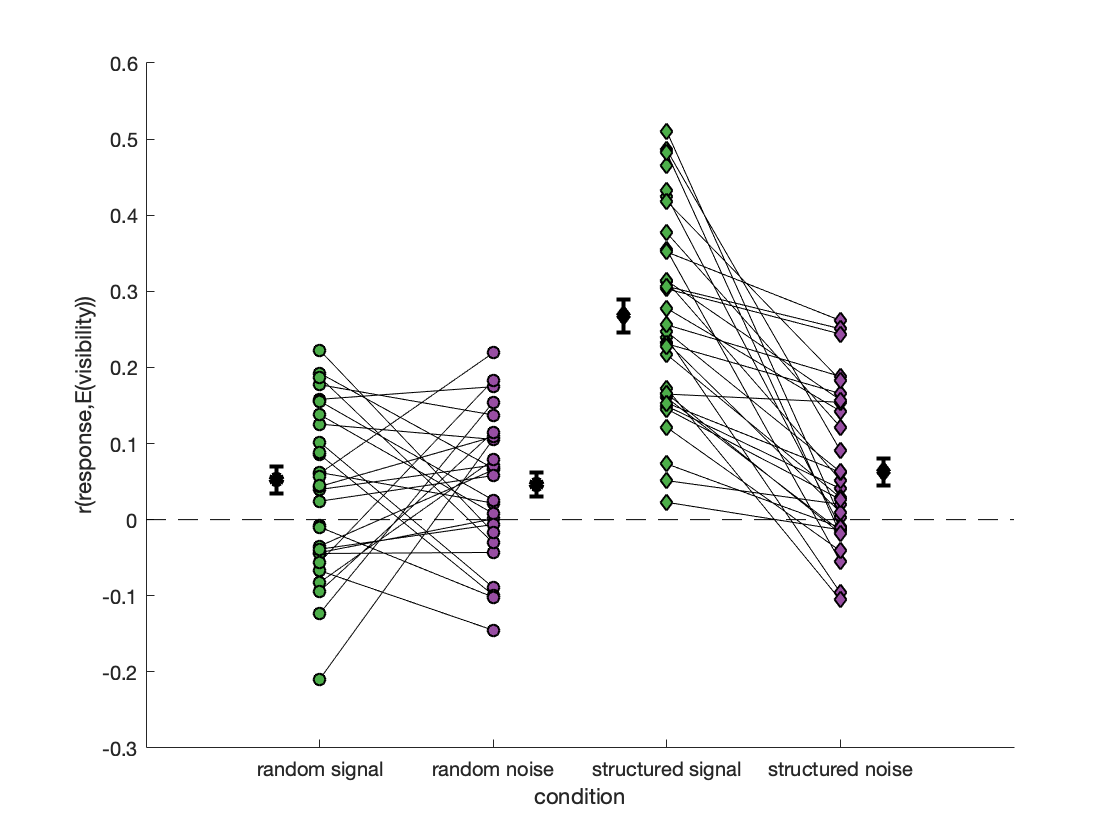

[rand_signal_EVresp_corr,rand_noise_EVresp_corr,struct_signal_EVresp_corr,struct_noise_EVresp_corr]...
    = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    subject = data_struct(subj);
    
    %calculate the E(visibility)-response correlation (Spearman's rank) for each participant in "yes" and "no" responses
    
    %random condition
    rand_signal_EVresp_corr(i_s) = nancorr(subject.RandomDemeanEV(subject.RandomSignal==1),...
        subject.RandomResp(subject.RandomSignal==1));
    rand_noise_EVresp_corr(i_s) = nancorr(subject.RandomDemeanEV(subject.RandomSignal==0),...
        subject.RandomResp(subject.RandomSignal==0));
    %structured condition
    struct_signal_EVresp_corr(i_s) = nancorr(subject.StructDemeanEV(subject.StructSignal==1),...
        subject.StructResp(subject.StructSignal==1));
    struct_noise_EVresp_corr(i_s) = nancorr(subject.StructDemeanEV(subject.StructSignal==0),...
        subject.StructResp(subject.StructSignal==0));
end

%useful values
[rand_signal_EVresp_corr_mean,rand_noise_EVresp_corr_mean,struct_signal_EVresp_corr_mean, struct_noise_EVresp_corr_mean] = ...
    deal(nanmean(rand_signal_EVresp_corr),nanmean(rand_noise_EVresp_corr),nanmean(struct_signal_EVresp_corr),nanmean(struct_noise_EVresp_corr));
[rand_signal_EVresp_corr_std,rand_noise_EVresp_corr_std,struct_signal_EVresp_corr_std, struct_noise_EVresp_corr_std] = ...
    deal(nanstd(rand_signal_EVresp_corr),nanstd(rand_noise_EVresp_corr),nanstd(struct_signal_EVresp_corr),nanstd(struct_noise_EVresp_corr));

%plot the E(visibility)-response correlation for each participant for both conditions and responses
figure; hold on;
plot(1:2,[rand_signal_EVresp_corr;rand_noise_EVresp_corr],'k');
plot(3:4,[struct_signal_EVresp_corr;struct_noise_EVresp_corr],'k');
scatter(ones(length(subj_list),1),rand_signal_EVresp_corr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_noise_EVresp_corr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_signal_EVresp_corr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(3,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_noise_EVresp_corr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(4,:),'LineWidth',1);
errorbar(0.75,rand_signal_EVresp_corr_mean,rand_signal_EVresp_corr_std/sqrt(length(rand_signal_EVresp_corr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_noise_EVresp_corr_mean,rand_noise_EVresp_corr_std/sqrt(length(rand_noise_EVresp_corr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_signal_EVresp_corr_mean,struct_signal_EVresp_corr_std/sqrt(length(struct_signal_EVresp_corr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_noise_EVresp_corr_mean,struct_noise_EVresp_corr_std/sqrt(length(struct_noise_EVresp_corr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylabel('r(response,E(visibility))');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random signal','random noise','structured signal','structured noise'})
plot([0,5],[0,0],'k--')
%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisResp','-dpng','-r600');

%check significance
[h,p,ci,stats] = ttest(rand_signal_EVresp_corr);
sprintf(['Significance test: r(response,E(visibility)) in random signal:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),E(visibility)) in random signal: t(33)=2.84, p=0.00760'

[h,p,ci,stats] = ttest(rand_noise_EVresp_corr);
sprintf(['Significance test: r(response,E(visibility)) in random noise:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),E(visibility)) in random noise: t(26)=2.55, p=0.01686'

[h,p,ci,stats] = ttest(rand_signal_EVresp_corr,rand_noise_EVresp_corr);
sprintf(['Significance test: Difference in r(response,E(visibility)) between signal and noise' ...
    ' in the random condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in r(p(yes),E(visibility)) between signal and noise in the random condition: t(25)=-0.25, p=0.80282'

[h,p,ci,stats] = ttest(struct_signal_EVresp_corr);
sprintf(['Significance test: r(response,E(visibility)) in structured signal:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),E(visibility)) in structured signal: t(34)=12.36, p=0.00000'

[h,p,ci,stats] = ttest(struct_noise_EVresp_corr);
sprintf(['Significance test: r(response,E(visibility)) in structured noise:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(p(yes),E(visibility)) in structured noise: t(29)=3.37, p=0.00214'

[h,p,ci,stats] = ttest(struct_signal_EVresp_corr,struct_noise_EVresp_corr);
sprintf(['Significance test: Difference in r(response,E(visibility)) between signal and noise:' ...
    ' in the random structured: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in r(p(yes),E(visibility)) between signal and noise: in the random structured: t(29)=7.52, p=0.00000'

[h,p,ci,stats] = ttest(rand_signal_EVresp_corr,struct_signal_EVresp_corr);
sprintf(['Significance test: Difference in r(response,E(visibility)) in signal trials between random' ...
    '  and structured: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in r(p(yes),E(visibility)) in signal trials between random  and structured: t(33)=-8.77, p=0.00000'

[h,p,ci,stats] = ttest(rand_noise_EVresp_corr,struct_noise_EVresp_corr);
sprintf(['Significance test: Difference in r(response,E(visibility)) in noise trials between random' ...
    '  and structured: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in r(p(yes),E(visibility)) in noise trials between random  and structured: t(24)=-0.33, p=0.74792'

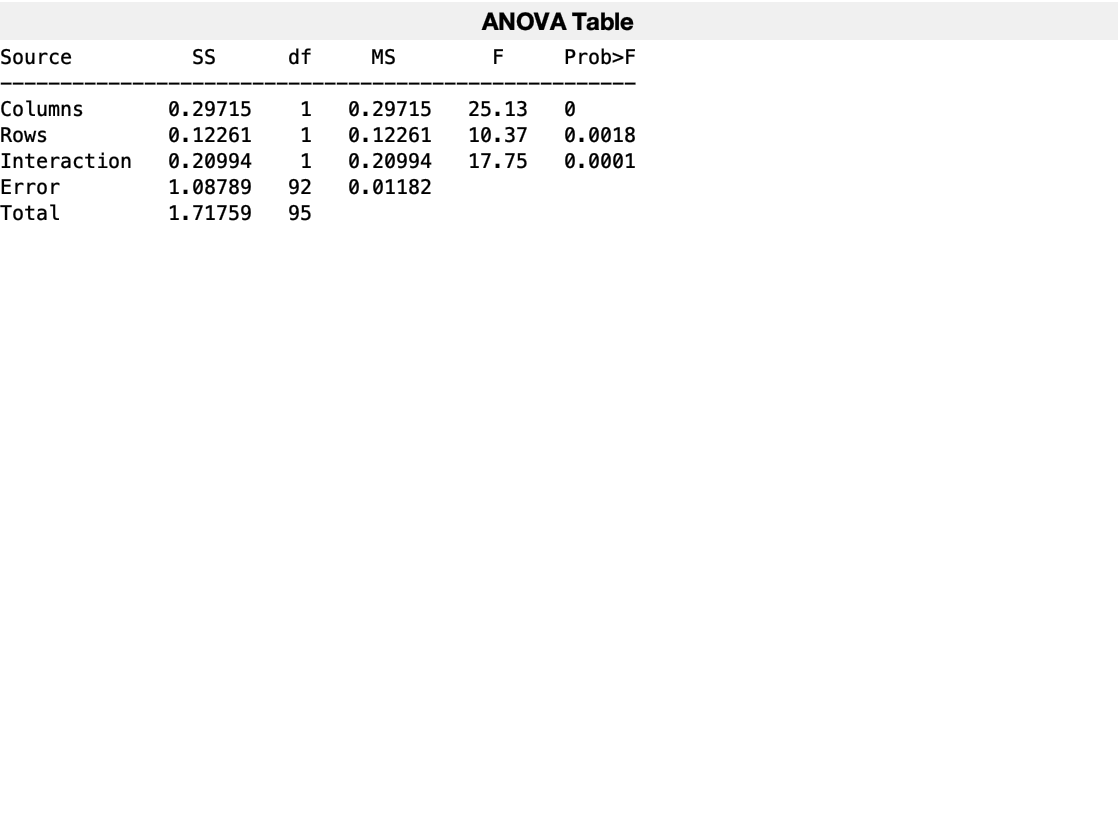

subj_mat_raw = [rand_signal_EVresp_corr',rand_noise_EVresp_corr',struct_signal_EVresp_corr',struct_noise_EVresp_corr'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_EVresp_corr_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_EVresp_corr_vec = [subj_mat(:,3);subj_mat(:,4)];
EVresp_corr_mat = [rand_EVresp_corr_vec,struct_EVresp_corr_vec];
[p,tbl,stats] = anova2(EVresp_corr_mat,length(EVresp_corr_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between structured and random conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between structured and random conditions: F(1,92)=25.13, p=0.00000'

sprintf(['Significance test: Between signal and noise responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between signal and noise responses: F(1,92)=10.37, p=0.00177'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,92)=17.75, p=0.00006'

## E(Visibility)-log(RT) correlation

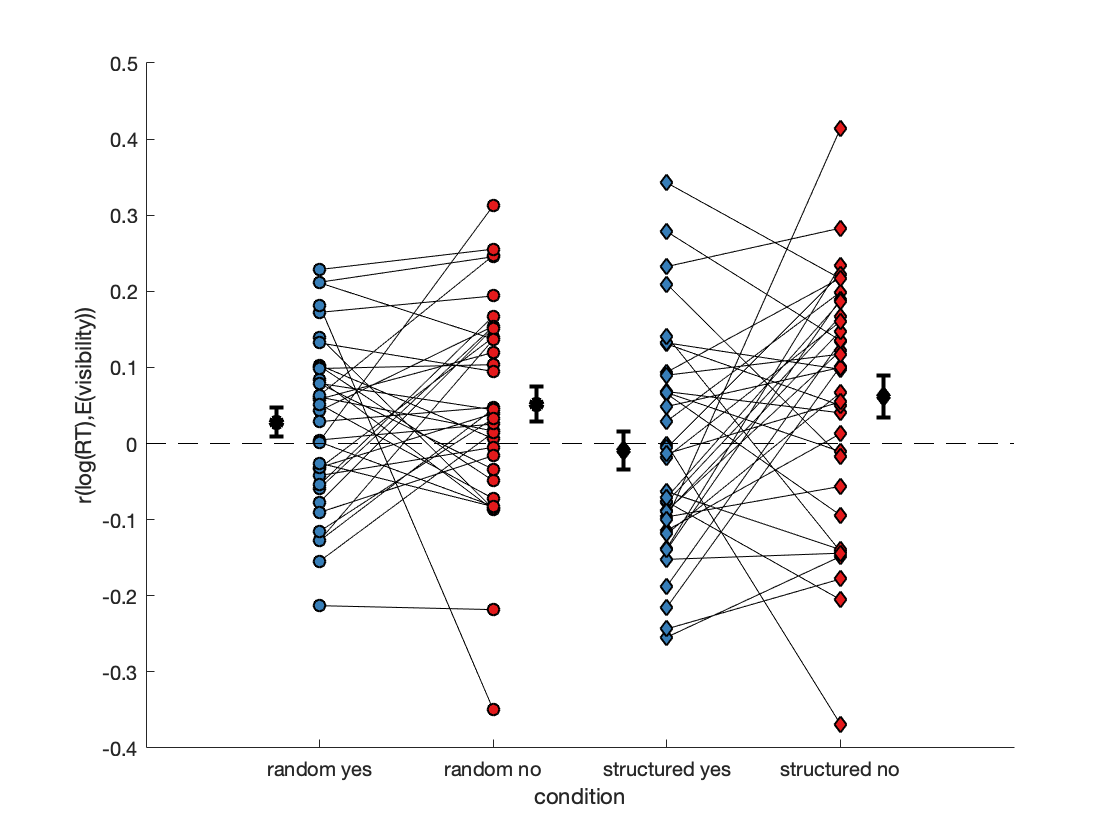

[rand_yes_EVRTcorr,struct_yes_EVRTcorr, rand_no_EVRTcorr, struct_no_EVRTcorr] = deal(nan(size(subj_list))); %initialise with NaN values

for i_s = 1:numel(subj_list)
    subj = subj_list{i_s};
    
    %extract demeaned log(RT) and E(visibility) vectors in both conditions
    demeaned_random_RT = data_struct(subj).RandomDemeanRT;
    demeaned_struct_RT = data_struct(subj).StructDemeanRT;
    demeaned_random_Evis = data_struct(subj).RandomDemeanEV;
    demeaned_struct_Evis = data_struct(subj).StructDemeanEV;
    
    %calculate the E(visibility)-log(RT) correlation (Spearman's rank) for each participant
    
    %random condition
    rand_yes_EVRTcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1),...
        demeaned_random_RT(data_struct(subj).RandomResp==1 & data_struct(subj).RandomCorrect==1));
    struct_yes_EVRTcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1),...
        demeaned_struct_RT(data_struct(subj).StructResp==1 & data_struct(subj).StructCorrect==1));
    %structured condition
    rand_no_EVRTcorr(i_s) = nancorr(demeaned_random_Evis(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1),...
        demeaned_random_RT(data_struct(subj).RandomResp==0  & data_struct(subj).RandomCorrect==1));
    struct_no_EVRTcorr(i_s) = nancorr(demeaned_struct_Evis(data_struct(subj).StructResp==0  & data_struct(subj).StructCorrect==1),...
        demeaned_struct_RT(data_struct(subj).StructResp==0 & data_struct(subj).StructCorrect==1));
end

%useful values
[rand_yes_EVRTcorr_mean,rand_no_EVRTcorr_mean,struct_yes_EVRTcorr_mean, struct_no_EVRTcorr_mean] = ...
    deal(nanmean(rand_yes_EVRTcorr),nanmean(rand_no_EVRTcorr),nanmean(struct_yes_EVRTcorr),nanmean(struct_no_EVRTcorr));
[rand_yes_EVRTcorr_std,rand_no_EVRTcorr_std,struct_yes_EVRTcorr_std, struct_no_EVRTcorr_std] = ...
    deal(nanstd(rand_yes_EVRTcorr),nanstd(rand_no_EVRTcorr),nanstd(struct_yes_EVRTcorr),nanstd(struct_no_EVRTcorr));

%plot the E(visibility)-log(RT) correlation for each participant for both conditions in "yes" and "no" responses
figure; hold on;
plot(1:2,[rand_yes_EVRTcorr;rand_no_EVRTcorr],'k');
plot(3:4,[struct_yes_EVRTcorr;struct_no_EVRTcorr],'k');
scatter(ones(length(subj_list),1),rand_yes_EVRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(2*ones(length(subj_list),1),rand_no_EVRTcorr,[],'MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
scatter(3*ones(length(subj_list),1),struct_yes_EVRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(2,:),'LineWidth',1);
scatter(4*ones(length(subj_list),1),struct_no_EVRTcorr,[], 'd','MarkerEdgeColor','k','MarkerFaceColor',cb(1,:),'LineWidth',1);
errorbar(0.75,rand_yes_EVRTcorr_mean,rand_yes_EVRTcorr_std/sqrt(length(rand_yes_EVRTcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.25,rand_no_EVRTcorr_mean,rand_no_EVRTcorr_std/sqrt(length(rand_no_EVRTcorr)),'ok','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(2.75,struct_yes_EVRTcorr_mean,struct_yes_EVRTcorr_std/sqrt(length(struct_yes_EVRTcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
errorbar(4.25,struct_no_EVRTcorr_mean,struct_no_EVRTcorr_std/sqrt(length(struct_no_EVRTcorr)),'dk','MarkerFaceColor',...
    'k','LineWidth',2)
ylabel('r(log(RT),E(visibility))');
xlim([0,5]); xlabel('condition');
set(gca,'xtick',[1:4],'xticklabel',{'random yes','random no','structured yes','structured no'})
plot([0,5],[0,0],'k--')

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/corrEVisRT','-dpng','-r600');

sprintf(['Random Yes r(RT,E(visibility)) (mean ± std) = %.2f ± %.2f; ' ...
    'Random No r(RT,E(visibility)) (mean, std) = %.2f ± %.2f'],...
    rand_yes_EVRTcorr_mean, rand_yes_EVRTcorr_std, rand_no_EVRTcorr_mean, rand_no_EVRTcorr_std)

ans = 'Random Yes r(RT,E(visibility)) (mean ± std) = 0.03 ± 0.11; Random No r(RT,E(visibility)) (mean, std) = 0.05 ± 0.14'

sprintf(['Structured Yes r(RT,E(visibility)) (mean ± std) = %.2f ± %.2f; ' ...
    'Structured No r(RT,E(visibility)) (mean, std) = %.2f ± %.2f'],...
    struct_yes_EVRTcorr_mean, struct_yes_EVRTcorr_std, struct_no_EVRTcorr_mean, struct_no_EVRTcorr_std)

ans = 'Structured Yes r(RT,E(visibility)) (mean ± std) = -0.01 ± 0.15; Structured No r(RT,E(visibility)) (mean, std) = 0.06 ± 0.16'

%significance test
[h,p,ci,stats] = ttest(rand_yes_EVRTcorr);
sprintf(['Significance test: r(RT,E(visibility)) in random yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,E(visibility)) in random yes: t(34)=1.50, p=0.14207'

[h,p,ci,stats] = ttest(rand_no_EVRTcorr);
sprintf(['Significance test: r(RT,E(visibility)) in random no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,E(visibility)) in random no: t(34)=2.23, p=0.03239'

[h,p,ci,stats] = ttest(struct_yes_EVRTcorr);
sprintf(['Significance test: r(RT,E(visibility)) in structured yes:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,E(visibility)) in structured yes: t(34)=-0.38, p=0.70355'

[h,p,ci,stats] = ttest(struct_no_EVRTcorr);
sprintf(['Significance test: r(RT,E(visibility)) in structured no:' ...
    ' t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: r(RT,E(visibility)) in structured no: t(34)=2.24, p=0.03203'

[h,p,ci,stats] = ttest(struct_no_EVRTcorr,rand_no_EVRTcorr);
sprintf(['Significance test: Difference in r(RT,E(visibility)) in no responses:' ...
    ' between structured and random t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in r(RT,E(visibility)) in no responses: between structured and random t(34)=0.29, p=0.77108'

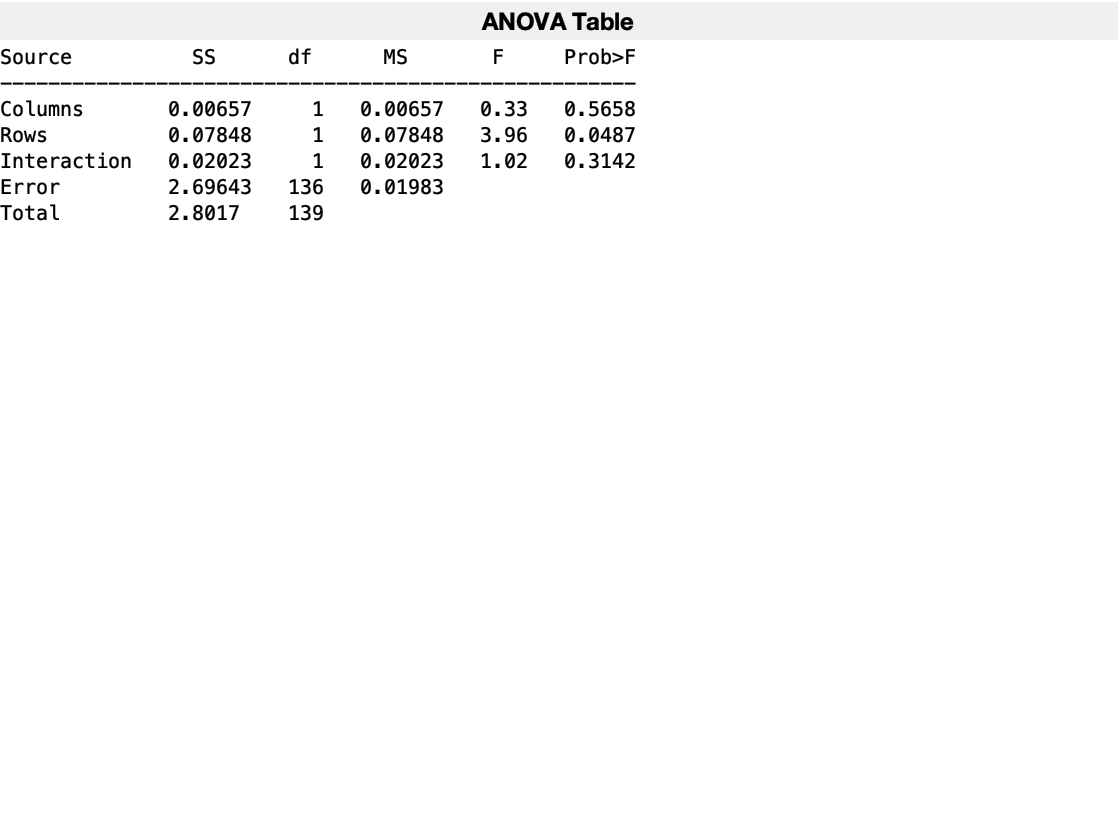

subj_mat_raw = [rand_yes_EVRTcorr',rand_no_EVRTcorr',struct_yes_EVRTcorr',struct_no_EVRTcorr'];
subj_mat = subj_mat_raw(all(~isnan(subj_mat_raw),2),:); %remove all rows (subjects) containing NaN values
rand_EVRTcorr_vec = [subj_mat(:,1);subj_mat(:,2)];
struct_EVRTcorr_vec = [subj_mat(:,3);subj_mat(:,4)];
EVRTcorr_mat = [rand_EVRTcorr_vec,struct_EVRTcorr_vec];
[p,tbl,stats] = anova2(EVRTcorr_mat,length(EVRTcorr_mat)/2);

column_df = cell2mat(tbl(2,3));
column_f = cell2mat(tbl(2,5));
column_p = p(1);
row_df = cell2mat(tbl(3,3));
row_f = cell2mat(tbl(3,5));
row_p = p(2);
interaction_df = cell2mat(tbl(4,3));
interaction_f = cell2mat(tbl(4,5));
interaction_p = p(3);

sprintf(['Significance test: Between structured and random conditions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],column_df,stats.df,column_f,column_p)

ans = 'Significance test: Between structured and random conditions: F(1,136)=0.33, p=0.56577'

sprintf(['Significance test: Between yes and no responses:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],row_df,stats.df,row_f,row_p)

ans = 'Significance test: Between yes and no responses: F(1,136)=3.96, p=0.04865'

sprintf(['Significance test: Interactions:' ...
    ' F(%d,%d)=%.2f, p=%.5f'],interaction_df,stats.df,interaction_f,interaction_p)

ans = 'Significance test: Interactions: F(1,136)=1.02, p=0.31423'

## Response-conditional ROC curves

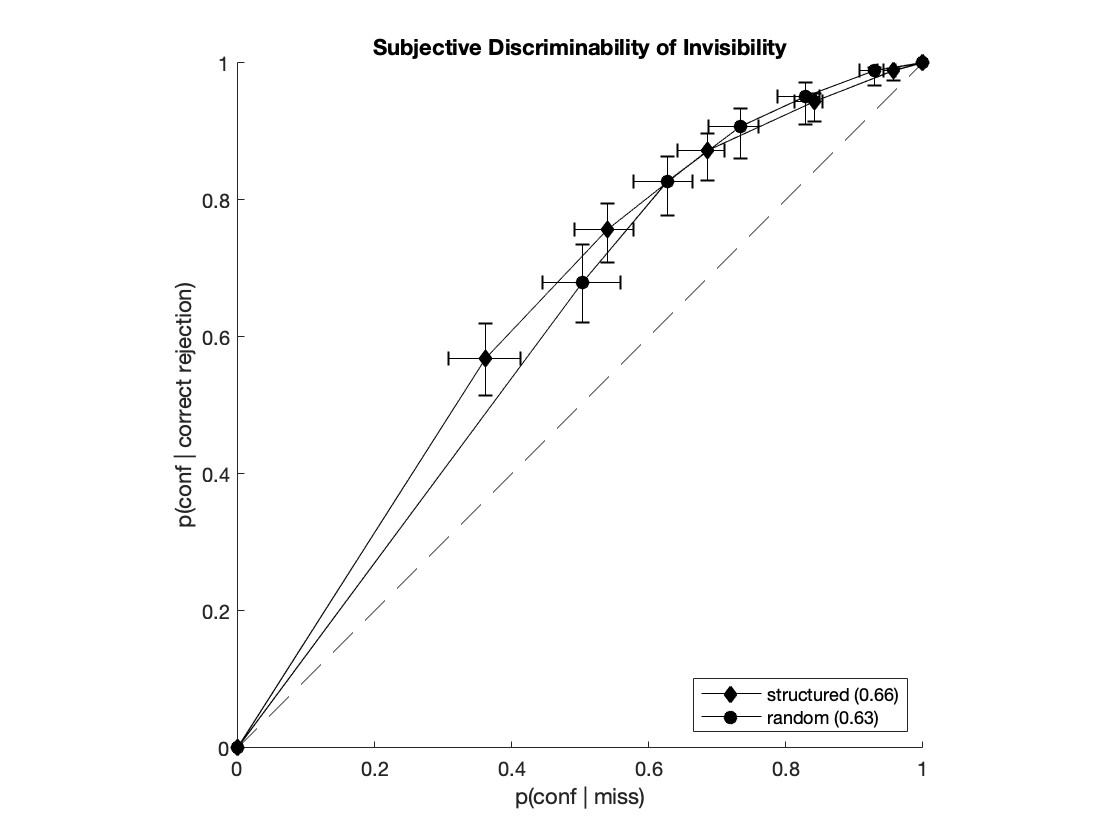

[StructSignalYesGroup, StructSignalNoGroup, StructNoiseYesGroup, StructNoiseNoGroup] = deal([]); %initialise with NaN values
[RandSignalYesGroup, RandSignalNoGroup, RandNoiseYesGroup, RandNoiseNoGroup] = deal([]); %initialise with NaN values
[nR_StructSignal,nR_StructNoise,nR_RandSignal,nR_RandNoise] = deal([]); %initialise with NaN values

for s=1:length(subj_list)
    subj = data_struct([subj_list{s}]);
    
    %break into taskXsignalXresponse
    StructSignalYes = histc(subj.StructConf(subj.StructSignal==1 & subj.StructResp==1),1:6);
    StructSignalNo = histc(subj.StructConf(subj.StructSignal==1 & subj.StructResp==0),1:6);
    StructNoiseYes = histc(subj.StructConf(subj.StructSignal==0 & subj.StructResp==1),1:6);
    StructNoiseNo = histc(subj.StructConf(subj.StructSignal==0 & subj.StructResp==0),1:6);
    
    RandSignalYes = histc(subj.RandomConf(subj.RandomSignal==1 & subj.RandomResp==1),1:6);
    RandSignalNo = histc(subj.RandomConf(subj.RandomSignal==1 & subj.RandomResp==0),1:6);
    RandNoiseYes = histc(subj.RandomConf(subj.RandomSignal==0 & subj.RandomResp==1),1:6);
    RandNoiseNo = histc(subj.RandomConf(subj.RandomSignal==0 & subj.RandomResp==0),1:6);
    
    nR_StructSignal(s,:) = [reshape(StructSignalNo(end:-1:1),1,[]) reshape(StructSignalYes,1,[])];
    nR_StructNoise(s,:) = [reshape(StructNoiseNo(end:-1:1),1,[]) reshape(StructNoiseYes,1,[])];
    nR_RandSignal(s,:) = [reshape(RandSignalNo(end:-1:1),1,[]) reshape(RandSignalYes,1,[])];
    nR_RandNoise(s,:) = [reshape(RandNoiseNo(end:-1:1),1,[]) reshape(RandNoiseYes,1,[])];
    
    
%     % plot random
%     
%     figure;
%     subplot(1,2,1);
%     hold on;
%     axis equal
%     
%     %random no responses
%     plot([0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)],...
%         [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)],'-ok');
%     
    RandNoAUC(s) = trapz([0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)],...
        [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)]);
    
    RandNoiseNoGroup(s,:) = [0; cumsum(RandNoiseNo(end:-1:1))/sum(RandNoiseNo)];
    RandSignalNoGroup(s,:) = [0; cumsum(RandSignalNo(end:-1:1))/sum(RandSignalNo)];
    
%     xlabel('p(conf|false positive)');
%     ylabel('p(conf|hit)');
%     title([subj_list{s}, ': random']);
%     set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
%     set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
%     refline(1,0);
%     legend('signal', 'noise', 'Location', 'southeast')
%     
%     % plot structured
%     subplot(1,2,2);
%     hold on;
%     axis equal
%     
%     %structured no responses
%     plot([0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)],...
%         [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)],'-ok');
%     
    StructNoAUC(s) = trapz([0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)],...
        [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)]);
    
    StructNoiseNoGroup(s,:) = [0; cumsum(StructNoiseNo(end:-1:1))/sum(StructNoiseNo)];
    StructSignalNoGroup(s,:) = [0; cumsum(StructSignalNo(end:-1:1))/sum(StructSignalNo)];
    
%     xlabel('p(conf|false positive)');
%     ylabel('p(conf|hit)');
%     title([subj_list{s}, ': structured']);
%     set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
%     set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
%     refline(1,0);
%     legend('signal', 'noise', 'Location', 'southeast')
%     set(0,'defaultAxesFontSize',10)
%     
end

%Group plot
figure;
ax1=subplot(1,1,1);
hold on;
axis equal
plot([0,1],[0,1],'k--')

%structured condition
errorbar(nanmean(StructSignalNoGroup),nanmean(StructNoiseNoGroup),nanstd(StructSignalNoGroup)/sqrt(length(subj_list)),nanstd(StructNoiseNoGroup)/sqrt(length(subj_list)),...
    nanstd(StructSignalNoGroup)/sqrt(length(subj_list)),nanstd(StructNoiseNoGroup)/sqrt(length(subj_list)),'k')
str_diamonds=plot(nanmean(StructSignalNoGroup),nanmean(StructNoiseNoGroup), '-dk', 'MarkerFaceColor', 'k');

%random condition
errorbar(nanmean(RandSignalNoGroup),nanmean(RandNoiseNoGroup),nanstd(RandSignalNoGroup)/sqrt(length(subj_list)),nanstd(RandNoiseNoGroup)/sqrt(length(subj_list)),...
    nanstd(RandSignalNoGroup)/sqrt(length(subj_list)),nanstd(RandNoiseNoGroup)/sqrt(length(subj_list)),'k')
rand_circles=plot(nanmean(RandSignalNoGroup),nanmean(RandNoiseNoGroup), '-ok', 'MarkerFaceColor', 'k');

%continue plotting
xlabel('p(conf | miss)');
ylabel('p(conf | correct rejection)');
title('Subjective Discriminability of Invisibility');
set(gca,'xtick',(0:0.2:1)); xlim([0,1]);
set(gca,'ytick',(0:0.2:1)); ylim([0,1]);
legend([str_diamonds,rand_circles],{sprintf('structured (%.02f)',nanmean(StructNoAUC)), sprintf('random (%.02f)',nanmean(RandNoAUC))}, 'Location', 'southeast')

%save figure
fig = gcf;
fig.PaperUnits = 'inches';
print('figures/SDI','-dpng','-r600');

sprintf(['Random No AUC (SDI) (mean ± std) = %.2f ± %.2f; ' ...
    'Structured No AUC (SDI) (mean, std) = %.2f ± %.2f'],...
    nanmean(RandNoAUC), nanstd(RandNoAUC), nanmean(StructNoAUC), nanstd(StructNoAUC))

ans = 'Random No AUC (SDI) (mean ± std) = 0.63 ± 0.11; Structured No AUC (SDI) (mean, std) = 0.66 ± 0.11'

%significance
[h,p,ci,stats] = ttest(StructNoAUC,0.5);
sprintf(['Significance test: AUC (SDI) in the ' ...
    'structured condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: AUC (SDI) in the structured condition: t(34)=8.22, p=0.00000'

[h,p,ci,stats] = ttest(RandNoAUC,0.5);
sprintf(['Significance test: AUC (SDI) in the ' ...
    'random condition: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: AUC (SDI) in the random condition: t(33)=7.08, p=0.00000'

[h,p,ci,stats] = ttest(StructNoAUC,RandNoAUC);
sprintf(['Significance test: Difference in AUC (SDI) between structured and ' ...
    'random conditions: t(%d)=%.2f, p=%.5f'],stats.df,stats.tstat,p)

ans = 'Significance test: Difference in AUC (SDI) between structured and random conditions: t(33)=1.03, p=0.31200'